# A script to join psth's from different experiemnts into a unified figure

% load experiment objects

cd('/lampllab/Data/Awake_AP2.5_ML4.0_A1/FVB/270721/757')
FVB103_757 = load('FVB103_757_shortten.mat')

FVB103_757 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]


cd('/home/ben/Z/FVB/270721/849')
FVB103_849 = load('FVB103_849_shortten.mat')

FVB103_849 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]


## PSTH for predicitons


FVB103_757.meanSound.aluminumMean = meanMatrix(FVB103_757.experiment.sound_events.aluminumEvents,1,30000)

FVB103_757 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]
     meanSound: [1×1 struct]


%figure; plot(mean(FVB103_757.experiment.sound_events.fullSound(FVB103_757.meanSound.aluminumMean)))
%hold on
FVB103_757.meanSound.mutedMean = meanMatrix(FVB103_757.experiment.sound_events.mutedEvents,1,30000)

FVB103_757 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]
     meanSound: [1×1 struct]


%plot(mean(FVB103_757.experiment.sound_events.fullSound(FVB103_757.meanSound.mutedMean)))
FVB103_757.meanSound.nonMean = meanMatrix(FVB103_757.experiment.sound_events.nonEvents,1,30000)

FVB103_757 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]
     meanSound: [1×1 struct]


%plot(mean(FVB103_757.experiment.sound_events.fullSound(FVB103_757.meanSound.nonMean)))

FVB103_849.meanSound.aluminumMean = meanMatrix(FVB103_849.experiment.sound_events.aluminumEvents,1,30000)

FVB103_849 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]
     meanSound: [1×1 struct]


%figure; plot(mean(FVB103_849.experiment.sound_events.fullSound(FVB103_849.meanSound.aluminumMean)))
%hold on
FVB103_849.meanSound.mutedMean = meanMatrix(FVB103_849.experiment.sound_events.mutedEvents,1,30000)

FVB103_849 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]
     meanSound: [1×1 struct]


%plot(mean(FVB103_849.experiment.sound_events.fullSound(FVB103_849.meanSound.mutedMean)))
FVB103_849.meanSound.nonMean = meanMatrix(FVB103_849.experiment.sound_events.nonEvents,1,30000)

FVB103_849 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]
     meanSound: [1×1 struct]


%plot(mean(FVB103_849.experiment.sound_events.fullSound(FVB103_849.meanSound.nonMean)))


FVB103_757.predictions.aluminumMean = meanMatrix(FVB103_757.experiment.predictedSound.events.aluminum,1,400)

FVB103_757 = struct with fields:
     experiment: [1×1 auditory_ephys_exp]
      meanSound: [1×1 struct]
    predictions: [1×1 struct]


%figure; plot(mean(FVB103_757.experiment.predictedSound.y(FVB103_757.predictions.aluminumMean)))
%hold on
FVB103_757.predictions.mutedMean = meanMatrix(FVB103_757.experiment.predictedSound.events.muted,1,400)

FVB103_757 = struct with fields:
     experiment: [1×1 auditory_ephys_exp]
      meanSound: [1×1 struct]
    predictions: [1×1 struct]


%plot(mean(FVB103_757.experiment.predictedSound.y(FVB103_757.predictions.mutedMean)))
FVB103_757.predictions.nonMean = meanMatrix(FVB103_757.experiment.predictedSound.events.non,1,400)

FVB103_757 = struct with fields:
     experiment: [1×1 auditory_ephys_exp]
      meanSound: [1×1 struct]
    predictions: [1×1 struct]


%plot(mean(FVB103_757.experiment.predictedSound.y(FVB103_757.predictions.nonMean)))

FVB103_849.predictions.aluminumMean = meanMatrix(FVB103_849.experiment.predictedSound.events.aluminum,1,400)

FVB103_849 = struct with fields:
     experiment: [1×1 auditory_ephys_exp]
      meanSound: [1×1 struct]
    predictions: [1×1 struct]


%figure; plot(mean(FVB103_849.experiment.predictedSound.y(FVB103_849.predictions.aluminumMean)))
%hold on
FVB103_849.predictions.mutedMean = meanMatrix(FVB103_849.experiment.predictedSound.events.muted,1,400)

FVB103_849 = struct with fields:
     experiment: [1×1 auditory_ephys_exp]
      meanSound: [1×1 struct]
    predictions: [1×1 struct]


%plot(mean(FVB103_849.experiment.predictedSound.y(FVB103_849.predictions.mutedMean)))
FVB103_849.predictions.nonMean = meanMatrix(FVB103_849.experiment.predictedSound.events.non,1,400)

FVB103_849 = struct with fields:
     experiment: [1×1 auditory_ephys_exp]
      meanSound: [1×1 struct]
    predictions: [1×1 struct]


%plot(mean(FVB103_849.experiment.predictedSound.y(FVB103_849.predictions.nonMean)))

epTimeVector = [-14999:15000]/30000

epTimeVector =    -0.5000   -0.4999   -0.4999   -0.4999   -0.4998   -0.4998   -0.4998   -0.4997   -0.4997   -0.4997   -0.4996   -0.4996   -0.4996   -0.4995   -0.4995   -0.4995   -0.4994   -0.4994   -0.4994   -0.4993   -0.4993   -0.4993   -0.4992   -0.4992   -0.4992   -0.4991   -0.4991   -0.4991   -0.4990   -0.4990   -0.4990   -0.4989   -0.4989   -0.4989   -0.4988   -0.4988   -0.4988   -0.4987   -0.4987   -0.4987   -0.4986   -0.4986   -0.4986   -0.4985   -0.4985   -0.4985   -0.4984   -0.4984   -0.4984   -0.4983


predTimeVector = [-199:200]/400

predTimeVector =    -0.4975   -0.4950   -0.4925   -0.4900   -0.4875   -0.4850   -0.4825   -0.4800   -0.4775   -0.4750   -0.4725   -0.4700   -0.4675   -0.4650   -0.4625   -0.4600   -0.4575   -0.4550   -0.4525   -0.4500   -0.4475   -0.4450   -0.4425   -0.4400   -0.4375   -0.4350   -0.4325   -0.4300   -0.4275   -0.4250   -0.4225   -0.4200   -0.4175   -0.4150   -0.4125   -0.4100   -0.4075   -0.4050   -0.4025   -0.4000   -0.3975   -0.3950   -0.3925   -0.3900   -0.3875   -0.3850   -0.3825   -0.3800   -0.3775   -0.3750


% for i =1:5:126
%     figure;
%     plot(epTimeVector,FVB103_757.experiment.sound_events.fullSound(FVB103_757.meanSound.aluminumMean(i,:)))
%     hold on
%     plot(predTimeVector,FVB103_757.experiment.predictedSound.y(FVB103_757.predictions.aluminumMean(i,:)))
% end

aluminumPredicted = (mean(FVB103_757.experiment.predictedSound.y(FVB103_757.predictions.aluminumMean)) + mean(FVB103_849.experiment.predictedSound.y(FVB103_849.predictions.aluminumMean)))/2

aluminumPredicted =     0.0313    0.0307    0.0305    0.0306    0.0309    0.0301    0.0310    0.0301    0.0309    0.0292    0.0287    0.0299    0.0296    0.0300    0.0283    0.0296    0.0297    0.0294    0.0294    0.0296    0.0294    0.0283    0.0287    0.0280    0.0287    0.0292    0.0293    0.0282    0.0288    0.0294    0.0283    0.0290    0.0282    0.0297    0.0284    0.0288    0.0290    0.0285    0.0290    0.0297    0.0279    0.0283    0.0287    0.0285    0.0293    0.0281    0.0289    0.0283    0.0288    0.0294


aluminumReal = (mean(FVB103_757.experiment.sound_events.fullSound(FVB103_757.meanSound.aluminumMean)) + mean(FVB103_849.experiment.sound_events.fullSound(FVB103_849.meanSound.aluminumMean)))/2

aluminumReal =     0.0277    0.0291    0.0310    0.0329    0.0282    0.0309    0.0305    0.0283    0.0307    0.0321    0.0264    0.0257    0.0278    0.0297    0.0310    0.0307    0.0285    0.0280    0.0313    0.0302    0.0286    0.0307    0.0282    0.0277    0.0288    0.0296    0.0301    0.0286    0.0275    0.0303    0.0292    0.0296    0.0293    0.0276    0.0277    0.0238    0.0289    0.0307    0.0308    0.0311    0.0268    0.0265    0.0301    0.0263    0.0278    0.0301    0.0310    0.0267    0.0311    0.0287



mutedPredicted = (mean(FVB103_757.experiment.predictedSound.y(FVB103_757.predictions.mutedMean)) + mean(FVB103_849.experiment.predictedSound.y(FVB103_849.predictions.mutedMean)))/2

mutedPredicted =     0.0348    0.0341    0.0335    0.0333    0.0332    0.0333    0.0327    0.0322    0.0329    0.0329    0.0328    0.0327    0.0318    0.0313    0.0316    0.0315    0.0314    0.0318    0.0315    0.0311    0.0319    0.0319    0.0317    0.0319    0.0313    0.0314    0.0314    0.0315    0.0314    0.0313    0.0306    0.0306    0.0311    0.0312    0.0313    0.0308    0.0312    0.0315    0.0311    0.0309    0.0314    0.0316    0.0316    0.0309    0.0312    0.0311    0.0305    0.0307    0.0309    0.0308


mutedReal = (mean(FVB103_757.experiment.sound_events.fullSound(FVB103_757.meanSound.mutedMean)) + mean(FVB103_849.experiment.sound_events.fullSound(FVB103_849.meanSound.mutedMean)))/2

mutedReal =     0.0255    0.0273    0.0240    0.0245    0.0256    0.0246    0.0246    0.0244    0.0244    0.0244    0.0249    0.0245    0.0233    0.0247    0.0242    0.0254    0.0249    0.0246    0.0233    0.0259    0.0251    0.0275    0.0265    0.0235    0.0266    0.0246    0.0256    0.0261    0.0251    0.0245    0.0257    0.0260    0.0244    0.0255    0.0255    0.0259    0.0249    0.0241    0.0251    0.0240    0.0247    0.0237    0.0235    0.0261    0.0234    0.0262    0.0242    0.0230    0.0233    0.0241



nonPredicted = (mean(FVB103_757.experiment.predictedSound.y(FVB103_757.predictions.nonMean)) + mean(FVB103_849.experiment.predictedSound.y(FVB103_849.predictions.nonMean)))/2

nonPredicted =     0.0338    0.0332    0.0335    0.0329    0.0326    0.0326    0.0325    0.0321    0.0319    0.0316    0.0320    0.0321    0.0321    0.0319    0.0313    0.0310    0.0312    0.0320    0.0316    0.0311    0.0312    0.0311    0.0307    0.0309    0.0306    0.0308    0.0313    0.0311    0.0309    0.0308    0.0308    0.0307    0.0305    0.0306    0.0305    0.0308    0.0306    0.0304    0.0301    0.0306    0.0308    0.0304    0.0305    0.0303    0.0303    0.0305    0.0309    0.0307    0.0302    0.0303


nonReal = (mean(FVB103_757.experiment.sound_events.fullSound(FVB103_757.meanSound.nonMean)) + mean(FVB103_849.experiment.sound_events.fullSound(FVB103_849.meanSound.nonMean)))/2

nonReal =     0.0266    0.0261    0.0248    0.0274    0.0276    0.0262    0.0264    0.0271    0.0250    0.0257    0.0278    0.0265    0.0263    0.0253    0.0268    0.0242    0.0263    0.0247    0.0273    0.0256    0.0247    0.0227    0.0253    0.0268    0.0255    0.0265    0.0277    0.0276    0.0264    0.0248    0.0226    0.0239    0.0254    0.0258    0.0269    0.0253    0.0279    0.0272    0.0256    0.0260    0.0248    0.0273    0.0274    0.0263    0.0260    0.0260    0.0263    0.0269    0.0257    0.0242


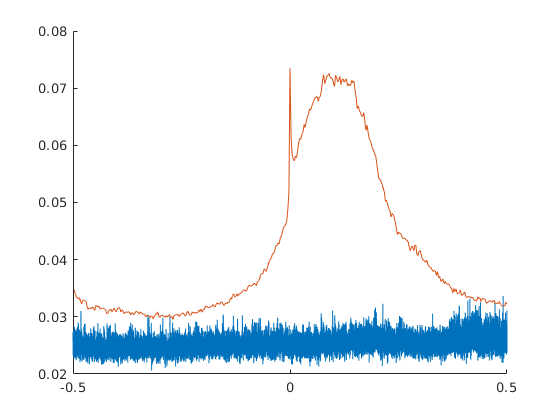

figure;
hold on
plot(epTimeVector,mutedReal)
plot(predTimeVector,mutedPredicted)

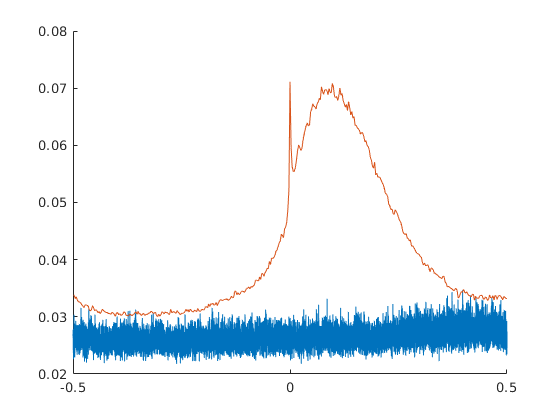

figure;
hold on
plot(epTimeVector,nonReal)
plot(predTimeVector,nonPredicted)

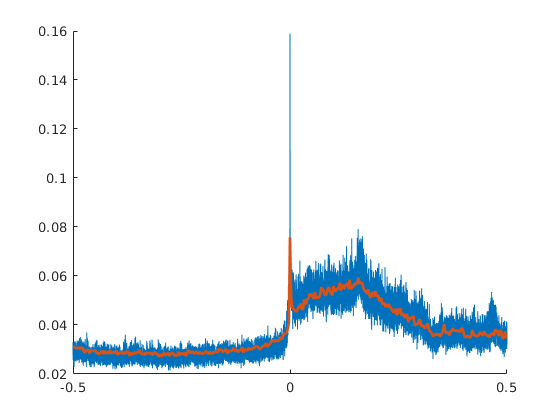

figure;


hold on
plot(epTimeVector,aluminumReal)
plot(predTimeVector,aluminumPredicted,'LineWidth',2)

% figure;
% plot(predTimeVector,mean(FVB103_757.predictions.sound(FVB103_757.predictions.aluminumMean)))
% hold on
% plot(epTimeVector,mean(FVB103_757.aud_data_norm(FVB103_757.meanSound.aluminumMean)))

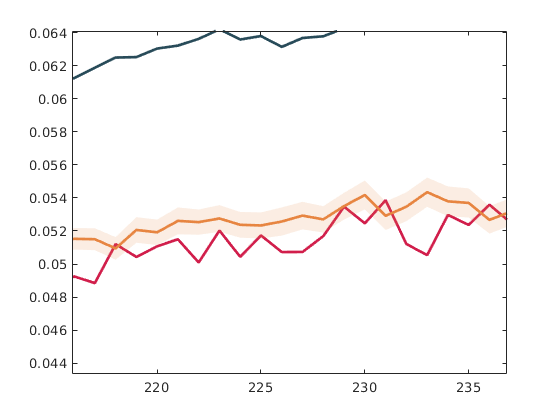

figure;

plot(aluminumPredicted)
hold on
plot(mutedPredicted)
hold on
plot(nonPredicted)

psth_alum = [FVB103_757.experiment.PSTHs.alum;FVB103_849.experiment.PSTHs.alum]

psth_alum =     0.0411    0.0137    0.0548    0.1096    0.0411    0.0411    0.0685    0.0685    0.0411    0.0274    0.0411    0.0959    0.0411    0.0548    0.0411    0.0411    0.0548    0.0137    0.0959    0.0822    0.0685    0.0548    0.0959    0.0548    0.0137    0.0411    0.0685    0.0548    0.0822    0.0822    0.0685    0.0411    0.0548    0.0411    0.0685    0.1370    0.0822    0.0274    0.0548    0.0685    0.0959    0.0822    0.0274    0.0685    0.0411    0.1233    0.0822    0.0548    0.0685    0.0411
    0.1096    0.1096    0.0685    0.0685    0.0959    0.1644    0.1781    0.1233    0.1233    0.1644    0.0685    0.0822    0.0685    0.1233    0.1644    0.0548    0.1233    0.0685    0.0822    0.1233    0.0959    0.1644    0.0959    0.1370    0.1370    0.1507    0.1781    0.1233    0.0959    0.0959    0.0685    0.0822    0.0685    0.0822    0.0959    0.1644    0.1644    0.1370    0.1096    0.1507    0.1781    0.1233    0.1507    0.1233    0.1644    0.1096    0.0548    0.0822    0.0

psth_mut = [FVB103_757.experiment.PSTHs.muted;FVB103_849.experiment.PSTHs.muted]

psth_mut =     0.0459    0.0917    0.0459    0.0550    0.1009    0.1009    0.0826    0.0826    0.0642    0.0550    0.0459    0.0826    0.0550    0.0734    0.0917    0.1009    0.1284    0.0734    0.0826    0.0826    0.1193    0.1101    0.0550    0.0550    0.0734    0.0550    0.0917    0.1009    0.0459    0.1284    0.1193    0.1009    0.0275    0.1560    0.0642    0.1193    0.1101    0.0917    0.1101    0.0917    0.0734    0.1101    0.0550    0.0642    0.1101    0.0550    0.0917    0.0459    0.0642    0.0550
    0.0917    0.1376    0.0459    0.0826    0.0642    0.0917    0.1009    0.1009    0.0367    0.0826    0.0734    0.0550    0.1101    0.0367    0.1009    0.0826    0.0826    0.0642    0.0642    0.0826    0.0459    0.1193    0.0734    0.0367    0.0459    0.0917    0.1009    0.1193    0.0550    0.1009    0.1468    0.0734    0.0550    0.2018    0.1284    0.0826    0.0367    0.0917    0.1376    0.1101    0.1009    0.1376    0.1009    0.1193    0.0734    0.1284    0.0734    0.0917    0.13

psth_non = [FVB103_757.experiment.PSTHs.non;FVB103_849.experiment.PSTHs.non]

psth_non =     0.0452    0.0516    0.0581    0.0581    0.0710    0.0645    0.0581    0.0968    0.0839    0.0323    0.0839    0.0710    0.0452    0.0452    0.0516    0.0774    0.1355    0.0903    0.0710    0.0774    0.0903    0.0645    0.0581    0.0387    0.0903    0.0839    0.0968    0.0516    0.0839    0.0968    0.0710    0.0516    0.0581    0.0774    0.0710    0.0516    0.0452    0.0452    0.0258    0.0710    0.0645    0.0903    0.0581    0.0516    0.0645    0.0645    0.1032    0.0323    0.1032    0.0968
    0.0903    0.1290    0.0968    0.1161    0.1032    0.0968    0.1097    0.1419    0.1677    0.1290    0.1032    0.1484    0.0968    0.1097    0.1742    0.1290    0.1032    0.0903    0.0774    0.0839    0.1290    0.1032    0.0839    0.0903    0.1097    0.0774    0.1097    0.1290    0.1355    0.1226    0.1032    0.1161    0.0710    0.1161    0.0645    0.1032    0.1097    0.0581    0.0839    0.0774    0.0839    0.0710    0.1226    0.1419    0.0968    0.1097    0.0645    0.0710    0.09

aud_units = [FVB103_757.experiment.Units.audUnits;size(FVB103_757.experiment.PSTHs.alum,1)+FVB103_849.experiment.Units.audUnits]

aud_units =      1
     2
     3
     4
     5
     6
    10
    12
    13
    15


psth_alum_aud = psth_alum(aud_units,:)

psth_alum_aud =     0.0411    0.0137    0.0548    0.1096    0.0411    0.0411    0.0685    0.0685    0.0411    0.0274    0.0411    0.0959    0.0411    0.0548    0.0411    0.0411    0.0548    0.0137    0.0959    0.0822    0.0685    0.0548    0.0959    0.0548    0.0137    0.0411    0.0685    0.0548    0.0822    0.0822    0.0685    0.0411    0.0548    0.0411    0.0685    0.1370    0.0822    0.0274    0.0548    0.0685    0.0959    0.0822    0.0274    0.0685    0.0411    0.1233    0.0822    0.0548    0.0685    0.0411
    0.1096    0.1096    0.0685    0.0685    0.0959    0.1644    0.1781    0.1233    0.1233    0.1644    0.0685    0.0822    0.0685    0.1233    0.1644    0.0548    0.1233    0.0685    0.0822    0.1233    0.0959    0.1644    0.0959    0.1370    0.1370    0.1507    0.1781    0.1233    0.0959    0.0959    0.0685    0.0822    0.0685    0.0822    0.0959    0.1644    0.1644    0.1370    0.1096    0.1507    0.1781    0.1233    0.1507    0.1233    0.1644    0.1096    0.0548    0.0822   

psth_mut_aud = psth_mut(aud_units,:)

psth_mut_aud =     0.0459    0.0917    0.0459    0.0550    0.1009    0.1009    0.0826    0.0826    0.0642    0.0550    0.0459    0.0826    0.0550    0.0734    0.0917    0.1009    0.1284    0.0734    0.0826    0.0826    0.1193    0.1101    0.0550    0.0550    0.0734    0.0550    0.0917    0.1009    0.0459    0.1284    0.1193    0.1009    0.0275    0.1560    0.0642    0.1193    0.1101    0.0917    0.1101    0.0917    0.0734    0.1101    0.0550    0.0642    0.1101    0.0550    0.0917    0.0459    0.0642    0.0550
    0.0917    0.1376    0.0459    0.0826    0.0642    0.0917    0.1009    0.1009    0.0367    0.0826    0.0734    0.0550    0.1101    0.0367    0.1009    0.0826    0.0826    0.0642    0.0642    0.0826    0.0459    0.1193    0.0734    0.0367    0.0459    0.0917    0.1009    0.1193    0.0550    0.1009    0.1468    0.0734    0.0550    0.2018    0.1284    0.0826    0.0367    0.0917    0.1376    0.1101    0.1009    0.1376    0.1009    0.1193    0.0734    0.1284    0.0734    0.0917    

psth_non_aud = psth_non(aud_units,:)

psth_non_aud =     0.0452    0.0516    0.0581    0.0581    0.0710    0.0645    0.0581    0.0968    0.0839    0.0323    0.0839    0.0710    0.0452    0.0452    0.0516    0.0774    0.1355    0.0903    0.0710    0.0774    0.0903    0.0645    0.0581    0.0387    0.0903    0.0839    0.0968    0.0516    0.0839    0.0968    0.0710    0.0516    0.0581    0.0774    0.0710    0.0516    0.0452    0.0452    0.0258    0.0710    0.0645    0.0903    0.0581    0.0516    0.0645    0.0645    0.1032    0.0323    0.1032    0.0968
    0.0903    0.1290    0.0968    0.1161    0.1032    0.0968    0.1097    0.1419    0.1677    0.1290    0.1032    0.1484    0.0968    0.1097    0.1742    0.1290    0.1032    0.0903    0.0774    0.0839    0.1290    0.1032    0.0839    0.0903    0.1097    0.0774    0.1097    0.1290    0.1355    0.1226    0.1032    0.1161    0.0710    0.1161    0.0645    0.1032    0.1097    0.0581    0.0839    0.0774    0.0839    0.0710    0.1226    0.1419    0.0968    0.1097    0.0645    0.0710    

for i = 1:40
    p_alumMut(i) = signrank(psth_alum_aud(:,i),psth_mut_aud(:,i))
    p_alumNon(i) = signrank(psth_alum_aud(:,i),psth_non_aud(:,i))
    p_nonMut(i) = signrank(psth_mut_aud(:,i),psth_non_aud(:,i))
end

p_alumMut = 0.1484

p_alumNon = 0.2645

p_nonMut = 0.5015

p_alumMut =     0.1484    0.4183


p_alumNon =     0.2645    0.4255


p_nonMut =     0.5015    0.6548


p_alumMut =     0.1484    0.4183    0.9111


p_alumNon =     0.2645    0.4255    0.9249


p_nonMut =     0.5015    0.6548    0.7695


p_alumMut =     0.1484    0.4183    0.9111    0.8233


p_alumNon =     0.2645    0.4255    0.9249    0.4941


p_nonMut =     0.5015    0.6548    0.7695    0.9638


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497


p_nonMut =     0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333


p_alumMut =     0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384


p_alumNon =     0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315


p_nonMut = 1×18
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850


p_alumMut = 1×19
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881


p_alumNon = 1×19
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913


p_nonMut = 1×19
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127


p_alumMut = 1×20
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148


p_alumNon = 1×20
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081


p_nonMut = 1×20
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908


p_alumMut = 1×21
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080


p_alumNon = 1×21
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009


p_nonMut = 1×21
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249


p_alumMut = 1×22
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150


p_alumNon = 1×22
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068


p_nonMut = 1×22
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215


p_alumMut = 1×23
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010


p_alumNon = 1×23
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037


p_nonMut = 1×23
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356


p_alumMut = 1×24
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424


p_alumNon = 1×24
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106


p_nonMut = 1×24
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930


p_alumMut = 1×25
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001


p_alumNon = 1×25
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056


p_nonMut = 1×25
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017


p_alumMut = 1×26
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007


p_alumNon = 1×26
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006


p_nonMut = 1×26
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571


p_alumMut = 1×27
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004


p_alumNon = 1×27
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000


p_nonMut = 1×27
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923


p_alumMut = 1×28
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095


p_alumNon = 1×28
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074


p_nonMut = 1×28
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101


p_alumMut = 1×29
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201


p_alumNon = 1×29
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675


p_nonMut = 1×29
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022


p_alumMut = 1×30
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×30
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×30
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


p_alumMut = 1×31
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×31
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×31
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


p_alumMut = 1×32
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×32
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×32
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


p_alumMut = 1×33
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×33
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×33
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


p_alumMut = 1×34
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×34
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×34
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


p_alumMut = 1×35
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×35
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×35
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


p_alumMut = 1×36
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×36
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×36
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


p_alumMut = 1×37
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×37
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×37
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


p_alumMut = 1×38
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×38
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×38
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


p_alumMut = 1×39
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×39
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×39
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


p_alumMut = 1×40
    0.1484    0.4183    0.9111    0.8233    0.8451    0.0038    0.4102    0.0115    0.0077    0.0763    0.0088    0.8125    0.3537    0.4689    0.0482    0.9535    0.1736    0.0384    0.7881    0.1148    0.0080    0.0150    0.0010    0.0424    0.0001    0.0007    0.0004    0.0095    0.0201    0.1127


p_alumNon = 1×40
    0.2645    0.4255    0.9249    0.4941    0.3718    0.0001    0.8192    0.8561    0.0624    0.0136    0.1215    0.2889    0.2422    0.0353    0.1487    0.0853    0.0497    0.0315    0.1913    0.0081    0.0009    0.0068    0.0037    0.0106    0.0056    0.0006    0.0000    0.0074    0.0675    0.0596


p_nonMut = 1×40
    0.5015    0.6548    0.7695    0.9638    0.4721    0.0857    0.0546    0.0373    0.3467    0.5473    0.2194    0.3607    0.2642    0.1115    0.6391    0.1758    0.9333    0.2850    0.1127    0.0908    0.9249    0.3215    0.3356    0.4930    0.3017    0.9571    0.1923    0.5101    0.7022    0.6769


mutSTD = std(psth_alum_aud)/sqrt(length(aud_units))

mutSTD =     0.0122    0.0108    0.0104    0.0124    0.0119    0.0117    0.0121    0.0114    0.0119    0.0127    0.0112    0.0129    0.0107    0.0109    0.0108    0.0128    0.0121    0.0155    0.0133    0.0135    0.0134    0.0150    0.0135    0.0131    0.0136    0.0158    0.0167    0.0137    0.0114    0.0137    0.0130    0.0144    0.0138    0.0145    0.0137    0.0129    0.0129    0.0162    0.0141    0.0108    0.0111    0.0109    0.0126    0.0130    0.0124    0.0120    0.0113    0.0110    0.0116    0.0112


alumSTD = std(psth_mut_aud)/sqrt(length(aud_units))

alumSTD =     0.0101    0.0106    0.0106    0.0107    0.0100    0.0097    0.0105    0.0092    0.0098    0.0106    0.0108    0.0104    0.0113    0.0109    0.0097    0.0109    0.0105    0.0119    0.0114    0.0114    0.0109    0.0106    0.0119    0.0105    0.0087    0.0108    0.0111    0.0110    0.0105    0.0111    0.0110    0.0134    0.0112    0.0110    0.0111    0.0104    0.0115    0.0123    0.0112    0.0133    0.0116    0.0102    0.0098    0.0108    0.0111    0.0115    0.0108    0.0096    0.0111    0.0102


nonSTD = std(psth_non)/sqrt(length(aud_units))

nonSTD =     0.0112    0.0104    0.0099    0.0101    0.0104    0.0090    0.0103    0.0103    0.0111    0.0096    0.0092    0.0103    0.0101    0.0094    0.0100    0.0100    0.0108    0.0095    0.0091    0.0089    0.0105    0.0100    0.0099    0.0093    0.0097    0.0093    0.0089    0.0085    0.0105    0.0102    0.0092    0.0087    0.0101    0.0101    0.0103    0.0103    0.0093    0.0094    0.0105    0.0078    0.0088    0.0085    0.0094    0.0100    0.0109    0.0094    0.0083    0.0118    0.0117    0.0090


time_vecor = FVB103_757.experiment.PSTHs.time_vector  ;

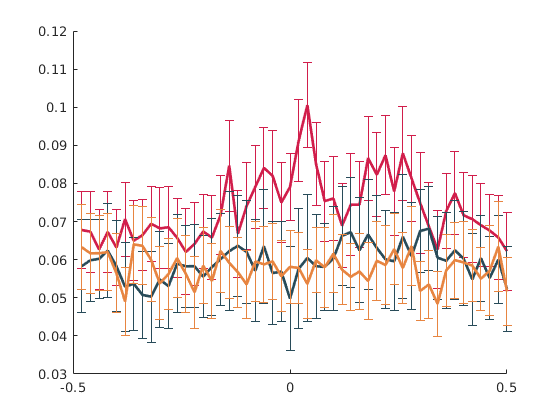

figure; 
hold on

plot(time_vecor,mean(psth_alum_aud),'LineWidth',2,'Color',FVB103_757.experiment.color.Aluminum)
errorbar(time_vecor,mean(psth_alum_aud),alumSTD,'LineWidth',0.1,'Color',FVB103_757.experiment.color.Aluminum)
hold on
plot(time_vecor,mean(psth_mut_aud),'LineWidth',2,'Color',FVB103_757.experiment.color.Muted)
errorbar(time_vecor,mean(psth_mut_aud),mutSTD,'LineWidth',0.1,'Color',FVB103_757.experiment.color.Muted)
plot(time_vecor,mean(psth_non_aud),'LineWidth',2,'Color',FVB103_757.experiment.color.noObject)
errorbar(time_vecor,mean(psth_non_aud),nonSTD,'LineWidth',0.1,'Color',FVB103_757.experiment.color.noObject)

optionsAl.handle = figure(1);
optionsAl.error = 'sem';
optionsAl.color_area = FVB103_757.experiment.color.Aluminum;   
optionsAl.color_line = FVB103_757.experiment.color.Aluminum;   
optionsAl.alpha = 0.1;        
optionsAl.line_width = 2;   
optionsAl.x_axis = time_vecor;

optionsMu.handle = figure(1);
optionsMu.error = 'sem';
optionsMu.color_area = FVB103_757.experiment.color.Muted;   
optionsMu.color_line = FVB103_757.experiment.color.Muted;   
optionsMu.alpha = 0.1;        
optionsMu.line_width = 2;   
optionsMu.x_axis = time_vecor;

optionsNo.handle = figure(1);
optionsNo.error = 'sem';
optionsNo.color_area = FVB103_757.experiment.color.noObject;   
optionsNo.color_line = FVB103_757.experiment.color.noObject;   
optionsNo.alpha = 0.1;        
optionsNo.line_width = 2;   
optionsNo.x_axis = time_vecor;

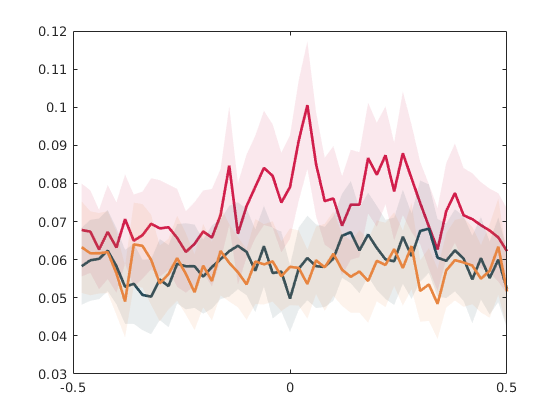

figure;
plot_areaerrorbar(psth_alum_aud,optionsAl)
hold on
plot_areaerrorbar(psth_mut_aud,optionsMu)
hold on
plot_areaerrorbar(psth_non_aud,optionsNo)

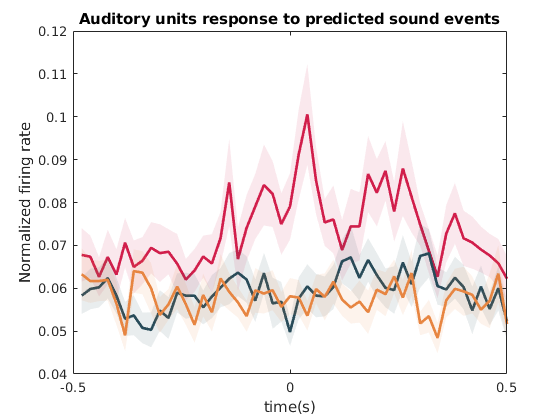

title('Auditory units response to predicted sound events')
xlabel('time(s)')
ylabel('Normalized firing rate')

legend('','Aluminum','','Muted','','No Object')
%text(time_vecor(p_alumMut < 0.025)-0.01,zeros(1,sum(p_alumMut < 0.025))+0.1,'**','color',FVB103_757.experiment.color.Muted)
%text(time_vecor(p_alumNon < 0.025)-0.01,zeros(1,sum(p_alumNon < 0.025))+0.095,'**','color',FVB103_757.experiment.color.noObject)
text(-0.45,0.1,'n=42','FontSize')

## PSTH for real sound on aluminum condition

aluminum_vector_757 = [];
for al = 1:length(FVB103_757.experiment.sound_events.aluminum)
    time_before = FVB103_757.experiment.sound_events.aluminum(al,2) - FVB103_757.experiment.artifacts_parameters.time_before*30
    time_after = FVB103_757.experiment.sound_events.aluminum(al,1) + FVB103_757.experiment.artifacts_parameters.time_after*30
    aluminum_temp = [time_after:time_before]
    aluminum_vector_757 = [aluminum_vector_757,aluminum_temp]
end

time_before = int64
6421339

time_after = int64
4861818

aluminum_temp = 1×1559522 int64 row vector
   4861818   4861819   4861820   4861821   4861822   4861823   4861824   4861825   4861826   4861827   4861828   4861829   4861830   4861831   4861832   4861833   4861834   4861835   4861836   4861837   4861838   4861839   4861840   4861841   4861842   4861843   4861844   4861845   4861846   4861847   4861848   4861849   4861850   4861851   4861852   4861853   4861854   4861855   4861856   4861857   4861858   4861859   4861860   4861861   4861862   4861863   4861864   4861865   4861866   4861867


aluminum_vector_757 = 1×1559522 int64 row vector
   4861818   4861819   4861820   4861821   4861822   4861823   4861824   4861825   4861826   4861827   4861828   4861829   4861830   4861831   4861832   4861833   4861834   4861835   4861836   4861837   4861838   4861839   4861840   4861841   4861842   4861843   4861844   4861845   4861846   4861847   4861848   4861849   4861850   4861851   4861852   4861853   4861854   4861855   4861856   4861857   4861858   4861859   4861860   4861861   4861862   4861863   4861864   4861865   4861866   4861867


time_before = int64
15838965

time_after = int64
14291438

aluminum_temp = 1×1547528 int64 row vector
   14291438   14291439   14291440   14291441   14291442   14291443   14291444   14291445   14291446   14291447   14291448   14291449   14291450   14291451   14291452   14291453   14291454   14291455   14291456   14291457   14291458   14291459   14291460   14291461   14291462   14291463   14291464   14291465   14291466   14291467   14291468   14291469   14291470   14291471   14291472   14291473   14291474   14291475   14291476   14291477   14291478   14291479   14291480   14291481   14291482   14291483   14291484   14291485   14291486   14291487


aluminum_vector_757 = 1×3107050 int64 row vector
   4861818   4861819   4861820   4861821   4861822   4861823   4861824   4861825   4861826   4861827   4861828   4861829   4861830   4861831   4861832   4861833   4861834   4861835   4861836   4861837   4861838   4861839   4861840   4861841   4861842   4861843   4861844   4861845   4861846   4861847   4861848   4861849   4861850   4861851   4861852   4861853   4861854   4861855   4861856   4861857   4861858   4861859   4861860   4861861   4861862   4861863   4861864   4861865   4861866   4861867


time_before = int64
17728491

time_after = int64
16168965

aluminum_temp = 1×1559527 int64 row vector
   16168965   16168966   16168967   16168968   16168969   16168970   16168971   16168972   16168973   16168974   16168975   16168976   16168977   16168978   16168979   16168980   16168981   16168982   16168983   16168984   16168985   16168986   16168987   16168988   16168989   16168990   16168991   16168992   16168993   16168994   16168995   16168996   16168997   16168998   16168999   16169000   16169001   16169002   16169003   16169004   16169005   16169006   16169007   16169008   16169009   16169010   16169011   16169012   16169013   16169014


aluminum_vector_757 = 1×4666577 int64 row vector
   4861818   4861819   4861820   4861821   4861822   4861823   4861824   4861825   4861826   4861827   4861828   4861829   4861830   4861831   4861832   4861833   4861834   4861835   4861836   4861837   4861838   4861839   4861840   4861841   4861842   4861843   4861844   4861845   4861846   4861847   4861848   4861849   4861850   4861851   4861852   4861853   4861854   4861855   4861856   4861857   4861858   4861859   4861860   4861861   4861862   4861863   4861864   4861865   4861866   4861867


time_before = int64
21483592

time_after = int64
19936063

aluminum_temp = 1×1547530 int64 row vector
   19936063   19936064   19936065   19936066   19936067   19936068   19936069   19936070   19936071   19936072   19936073   19936074   19936075   19936076   19936077   19936078   19936079   19936080   19936081   19936082   19936083   19936084   19936085   19936086   19936087   19936088   19936089   19936090   19936091   19936092   19936093   19936094   19936095   19936096   19936097   19936098   19936099   19936100   19936101   19936102   19936103   19936104   19936105   19936106   19936107   19936108   19936109   19936110   19936111   19936112


aluminum_vector_757 = 1×6214107 int64 row vector
   4861818   4861819   4861820   4861821   4861822   4861823   4861824   4861825   4861826   4861827   4861828   4861829   4861830   4861831   4861832   4861833   4861834   4861835   4861836   4861837   4861838   4861839   4861840   4861841   4861842   4861843   4861844   4861845   4861846   4861847   4861848   4861849   4861850   4861851   4861852   4861853   4861854   4861855   4861856   4861857   4861858   4861859   4861860   4861861   4861862   4861863   4861864   4861865   4861866   4861867


time_before = int64
23373119

time_after = int64
21813592

aluminum_temp = 1×1559528 int64 row vector
   21813592   21813593   21813594   21813595   21813596   21813597   21813598   21813599   21813600   21813601   21813602   21813603   21813604   21813605   21813606   21813607   21813608   21813609   21813610   21813611   21813612   21813613   21813614   21813615   21813616   21813617   21813618   21813619   21813620   21813621   21813622   21813623   21813624   21813625   21813626   21813627   21813628   21813629   21813630   21813631   21813632   21813633   21813634   21813635   21813636   21813637   21813638   21813639   21813640   21813641


aluminum_vector_757 = 1×7773635 int64 row vector
   4861818   4861819   4861820   4861821   4861822   4861823   4861824   4861825   4861826   4861827   4861828   4861829   4861830   4861831   4861832   4861833   4861834   4861835   4861836   4861837   4861838   4861839   4861840   4861841   4861842   4861843   4861844   4861845   4861846   4861847   4861848   4861849   4861850   4861851   4861852   4861853   4861854   4861855   4861856   4861857   4861858   4861859   4861860   4861861   4861862   4861863   4861864   4861865   4861866   4861867


time_before = int64
27134177

time_after = int64
25580648

aluminum_temp = 1×1553530 int64 row vector
   25580648   25580649   25580650   25580651   25580652   25580653   25580654   25580655   25580656   25580657   25580658   25580659   25580660   25580661   25580662   25580663   25580664   25580665   25580666   25580667   25580668   25580669   25580670   25580671   25580672   25580673   25580674   25580675   25580676   25580677   25580678   25580679   25580680   25580681   25580682   25580683   25580684   25580685   25580686   25580687   25580688   25580689   25580690   25580691   25580692   25580693   25580694   25580695   25580696   25580697


aluminum_vector_757 = 1×9327165 int64 row vector
   4861818   4861819   4861820   4861821   4861822   4861823   4861824   4861825   4861826   4861827   4861828   4861829   4861830   4861831   4861832   4861833   4861834   4861835   4861836   4861837   4861838   4861839   4861840   4861841   4861842   4861843   4861844   4861845   4861846   4861847   4861848   4861849   4861850   4861851   4861852   4861853   4861854   4861855   4861856   4861857   4861858   4861859   4861860   4861861   4861862   4861863   4861864   4861865   4861866   4861867


aluminum_sound_757 = FVB103_757.experiment.sound_events.fullSound(aluminum_vector_757)

aluminum_sound_757 =     0.0297    0.0817    0.0337    0.0223    0.0483    0.0203    0.0073    0.0263    0.0747    0.0237    0.0307    0.0177    0.0033    0.0043    0.0297    0.0697    0.0497    0.0067    0.0283    0.0337    0.0187    0.0457    0.0077    0.0223    0.0223    0.0097    0.0217    0.0477    0.0337    0.0097    0.0037    0.0053    0.0197    0.0257    0.0547    0.0023    0.0923    0.1123    0.0183    0.0283    0.0017    0.0447    0.0577    0.0697    0.0223    0.0657    0.0217    0.0217    0.0507    0.0577


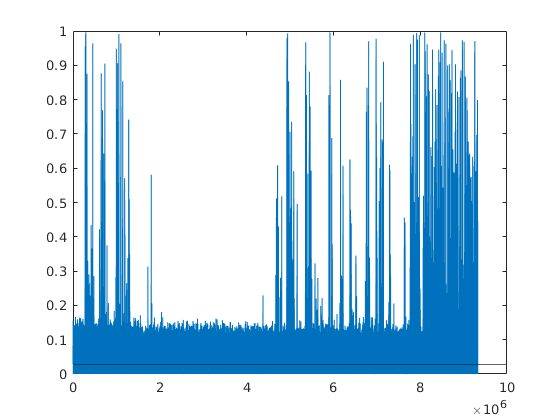

thr = 0.2500

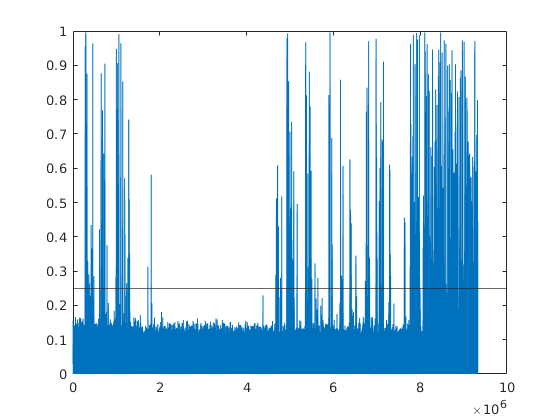

thr = 0.2500

times_sound =       281042
      340696
      364955
      377109
      416749
      454985
      480506
      610837
      639077
      707699


times_sound = event_detection(aluminum_sound_757,30000*0.4)

times_sound_full = double(aluminum_vector_757(times_sound))

times_sound_full =      5142859     5202513     5226772     5238926     5278566     5316802     5342323     5472654     5500894     5569516     5589141     5644960     5850439     5913336     5958831     5998627     6050686     6097373     6125371     6144625    14455362    14534651    19940873    20051513    20078534    20193104    20263219    20300226    20430046    20627737    20691278    20773263    20844567    20912045    21164288    21191995    21230231    21243931    21428492    21457663    21477578    21980498    21994756    22113450    22335502    22354391    22400328    22576070    22655526    22672252


timeWind = 1

timeWind = 1

numBins = 20

numBins = 20

rasters_aluminum_757 = {}


rasters_aluminum_757 =

  0×0 empty cell array



psth_aluminum_757 = []


psth_aluminum_757 =

     []



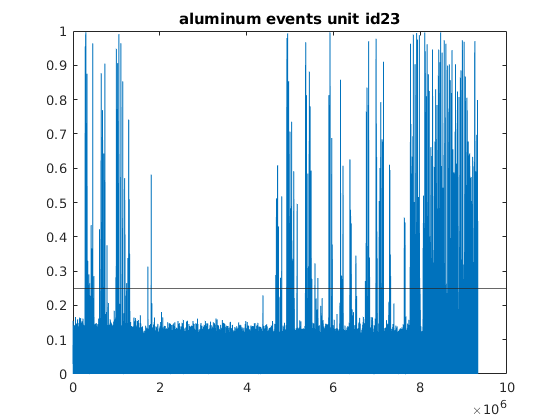

for un = 1:length(FVB103_757.experiment.Units.good.id)
    rasters_aluminum_757{un} = createRaster(times_sound_full,FVB103_757.experiment.Units.good.times(un,:),timeWind);
    title(['aluminum events unit id',num2str(un)])
    psth_aluminum_757(un,:) = psth(rasters_aluminum_757{un},numBins);
end

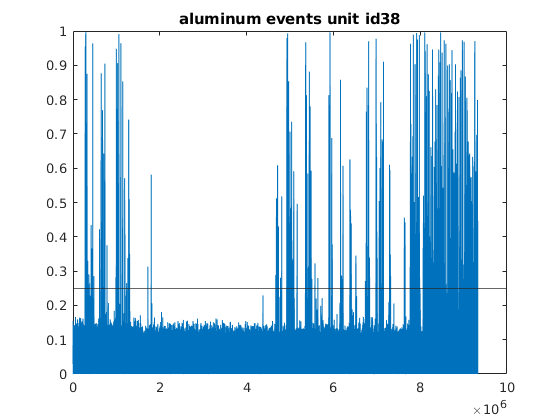


for un_1 = 1:length(FVB103_757.experiment.Units.mua.id)
    rasters_aluminum_757{un + un_1} = createRaster(times_sound_full,FVB103_757.experiment.Units.mua.times(un_1,:),timeWind);
    title(['aluminum events unit id',num2str(un_1+un)])
    psth_aluminum_757(un_1+un,:) = psth(rasters_aluminum_757{un_1+un},numBins);
end

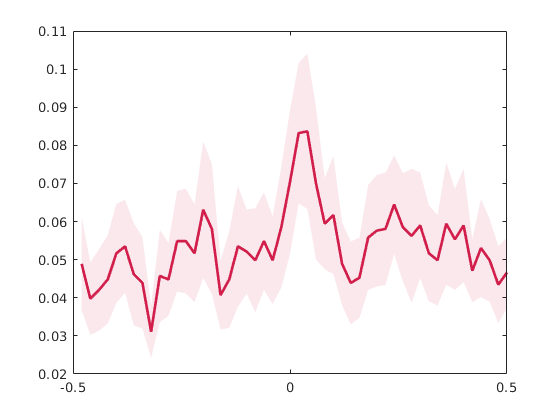

optionsS.handle = figure(2);
optionsS.error = 'sem';
optionsS.color_area = FVB103_757.experiment.color.Aluminum;   
optionsS.color_line = FVB103_757.experiment.color.Aluminum;   
optionsS.alpha = 0.1;        
optionsS.line_width = 2;   
optionsS.x_axis = time_vecor;
figure; plot_areaerrorbar(psth_aluminum_757(FVB103_757.experiment.evokedEvents.pVal(:,2)==1,:),optionsS)

aluminumReal_757 = meanMatrix(times_sound_full,1,30000)

aluminumReal_757 =      5127860     5127861     5127862     5127863     5127864     5127865     5127866     5127867     5127868     5127869     5127870     5127871     5127872     5127873     5127874     5127875     5127876     5127877     5127878     5127879     5127880     5127881     5127882     5127883     5127884     5127885     5127886     5127887     5127888     5127889     5127890     5127891     5127892     5127893     5127894     5127895     5127896     5127897     5127898     5127899     5127900     5127901     5127902     5127903     5127904     5127905     5127906     5127907     5127908     5127909
     5187514     5187515     5187516     5187517     5187518     5187519     5187520     5187521     5187522     5187523     5187524     5187525     5187526     5187527     5187528     5187529     5187530     5187531     5187532     5187533     5187534     5187535     5187536     5187537     5187538     5187539     5187540     5187541     5187542     5187543     5187544     518

aluminum_vector_849 = [];
for al = 1:length(FVB103_849.experiment.sound_events.aluminum)
    time_before = FVB103_849.experiment.sound_events.aluminum(al,2) - FVB103_849.experiment.artifacts_parameters.time_before*30
    time_after = FVB103_849.experiment.sound_events.aluminum(al,1) + FVB103_849.experiment.artifacts_parameters.time_after*30
    aluminum_temp = [time_after:time_before]
    aluminum_vector_849 = [aluminum_vector_849,aluminum_temp]
end

time_before = int64
15844759

time_after = int64
14291228

aluminum_temp = 1×1553532 int64 row vector
   14291228   14291229   14291230   14291231   14291232   14291233   14291234   14291235   14291236   14291237   14291238   14291239   14291240   14291241   14291242   14291243   14291244   14291245   14291246   14291247   14291248   14291249   14291250   14291251   14291252   14291253   14291254   14291255   14291256   14291257   14291258   14291259   14291260   14291261   14291262   14291263   14291264   14291265   14291266   14291267   14291268   14291269   14291270   14291271   14291272   14291273   14291274   14291275   14291276   14291277


aluminum_vector_849 = 1×1553532 int64 row vector
   14291228   14291229   14291230   14291231   14291232   14291233   14291234   14291235   14291236   14291237   14291238   14291239   14291240   14291241   14291242   14291243   14291244   14291245   14291246   14291247   14291248   14291249   14291250   14291251   14291252   14291253   14291254   14291255   14291256   14291257   14291258   14291259   14291260   14291261   14291262   14291263   14291264   14291265   14291266   14291267   14291268   14291269   14291270   14291271   14291272   14291273   14291274   14291275   14291276   14291277


time_before = int64
21495390

time_after = int64
19941859

aluminum_temp = 1×1553532 int64 row vector
   19941859   19941860   19941861   19941862   19941863   19941864   19941865   19941866   19941867   19941868   19941869   19941870   19941871   19941872   19941873   19941874   19941875   19941876   19941877   19941878   19941879   19941880   19941881   19941882   19941883   19941884   19941885   19941886   19941887   19941888   19941889   19941890   19941891   19941892   19941893   19941894   19941895   19941896   19941897   19941898   19941899   19941900   19941901   19941902   19941903   19941904   19941905   19941906   19941907   19941908


aluminum_vector_849 = 1×3107064 int64 row vector
   14291228   14291229   14291230   14291231   14291232   14291233   14291234   14291235   14291236   14291237   14291238   14291239   14291240   14291241   14291242   14291243   14291244   14291245   14291246   14291247   14291248   14291249   14291250   14291251   14291252   14291253   14291254   14291255   14291256   14291257   14291258   14291259   14291260   14291261   14291262   14291263   14291264   14291265   14291266   14291267   14291268   14291269   14291270   14291271   14291272   14291273   14291274   14291275   14291276   14291277


time_before = int64
27145965

time_after = int64
25592440

aluminum_temp = 1×1553526 int64 row vector
   25592440   25592441   25592442   25592443   25592444   25592445   25592446   25592447   25592448   25592449   25592450   25592451   25592452   25592453   25592454   25592455   25592456   25592457   25592458   25592459   25592460   25592461   25592462   25592463   25592464   25592465   25592466   25592467   25592468   25592469   25592470   25592471   25592472   25592473   25592474   25592475   25592476   25592477   25592478   25592479   25592480   25592481   25592482   25592483   25592484   25592485   25592486   25592487   25592488   25592489


aluminum_vector_849 = 1×4660590 int64 row vector
   14291228   14291229   14291230   14291231   14291232   14291233   14291234   14291235   14291236   14291237   14291238   14291239   14291240   14291241   14291242   14291243   14291244   14291245   14291246   14291247   14291248   14291249   14291250   14291251   14291252   14291253   14291254   14291255   14291256   14291257   14291258   14291259   14291260   14291261   14291262   14291263   14291264   14291265   14291266   14291267   14291268   14291269   14291270   14291271   14291272   14291273   14291274   14291275   14291276   14291277


time_before = int64
30907011

time_after = int64
29353488

aluminum_temp = 1×1553524 int64 row vector
   29353488   29353489   29353490   29353491   29353492   29353493   29353494   29353495   29353496   29353497   29353498   29353499   29353500   29353501   29353502   29353503   29353504   29353505   29353506   29353507   29353508   29353509   29353510   29353511   29353512   29353513   29353514   29353515   29353516   29353517   29353518   29353519   29353520   29353521   29353522   29353523   29353524   29353525   29353526   29353527   29353528   29353529   29353530   29353531   29353532   29353533   29353534   29353535   29353536   29353537


aluminum_vector_849 = 1×6214114 int64 row vector
   14291228   14291229   14291230   14291231   14291232   14291233   14291234   14291235   14291236   14291237   14291238   14291239   14291240   14291241   14291242   14291243   14291244   14291245   14291246   14291247   14291248   14291249   14291250   14291251   14291252   14291253   14291254   14291255   14291256   14291257   14291258   14291259   14291260   14291261   14291262   14291263   14291264   14291265   14291266   14291267   14291268   14291269   14291270   14291271   14291272   14291273   14291274   14291275   14291276   14291277


time_before = int64
34668095

time_after = int64
33114531

aluminum_temp = 1×1553565 int64 row vector
   33114531   33114532   33114533   33114534   33114535   33114536   33114537   33114538   33114539   33114540   33114541   33114542   33114543   33114544   33114545   33114546   33114547   33114548   33114549   33114550   33114551   33114552   33114553   33114554   33114555   33114556   33114557   33114558   33114559   33114560   33114561   33114562   33114563   33114564   33114565   33114566   33114567   33114568   33114569   33114570   33114571   33114572   33114573   33114574   33114575   33114576   33114577   33114578   33114579   33114580


aluminum_vector_849 = 1×7767679 int64 row vector
   14291228   14291229   14291230   14291231   14291232   14291233   14291234   14291235   14291236   14291237   14291238   14291239   14291240   14291241   14291242   14291243   14291244   14291245   14291246   14291247   14291248   14291249   14291250   14291251   14291252   14291253   14291254   14291255   14291256   14291257   14291258   14291259   14291260   14291261   14291262   14291263   14291264   14291265   14291266   14291267   14291268   14291269   14291270   14291271   14291272   14291273   14291274   14291275   14291276   14291277


time_before = int64
38435130

time_after = int64
36875614

aluminum_temp = 1×1559517 int64 row vector
   36875614   36875615   36875616   36875617   36875618   36875619   36875620   36875621   36875622   36875623   36875624   36875625   36875626   36875627   36875628   36875629   36875630   36875631   36875632   36875633   36875634   36875635   36875636   36875637   36875638   36875639   36875640   36875641   36875642   36875643   36875644   36875645   36875646   36875647   36875648   36875649   36875650   36875651   36875652   36875653   36875654   36875655   36875656   36875657   36875658   36875659   36875660   36875661   36875662   36875663


aluminum_vector_849 = 1×9327196 int64 row vector
   14291228   14291229   14291230   14291231   14291232   14291233   14291234   14291235   14291236   14291237   14291238   14291239   14291240   14291241   14291242   14291243   14291244   14291245   14291246   14291247   14291248   14291249   14291250   14291251   14291252   14291253   14291254   14291255   14291256   14291257   14291258   14291259   14291260   14291261   14291262   14291263   14291264   14291265   14291266   14291267   14291268   14291269   14291270   14291271   14291272   14291273   14291274   14291275   14291276   14291277


aluminum_sound_849 = FVB103_849.experiment.sound_events.fullSound(aluminum_vector_849)

aluminum_sound_849 =     0.0796    0.0204    0.0136    0.0386    0.0184    0.0336    0.0286    0.0406    0.0456    0.0496    0.0144    0.0423    0.0323    0.0227    0.0297    0.0063    0.0333    0.0843    0.0353    0.0297    0.0097    0.0183    0.0353    0.0863    0.0347    0.0257    0.0017    0.0223    0.0493    0.0307    0.0663    0.0303    0.0143    0.0017    0.0103    0.0463    0.0103    0.0563    0.0157    0.0417    0.0417    0.0423    0.0677    0.0757    0.0127    0.0133    0.0557    0.0427    0.0323    0.0263


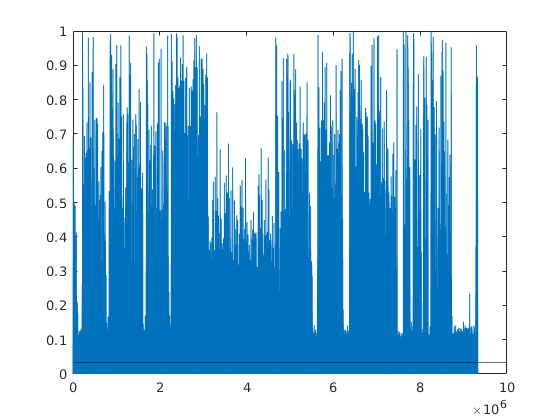

thr = 0.3000

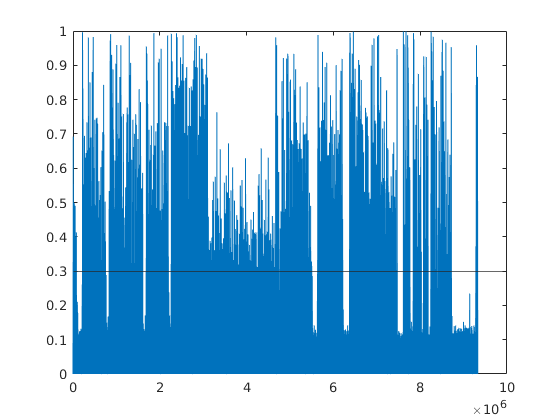

thr = 0.3500

times_sound_1 =        49948
       77829
      215233
      281079
      321629
      391036
      502946
      522621
      567782
      617638


times_sound_1 = event_detection(aluminum_sound_849(1:9327165),30000*0.4)

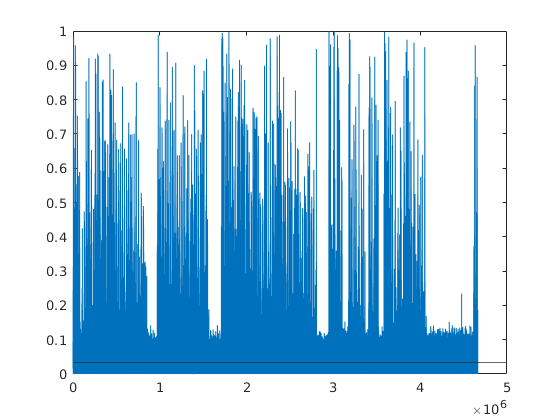

thr = 0.3500

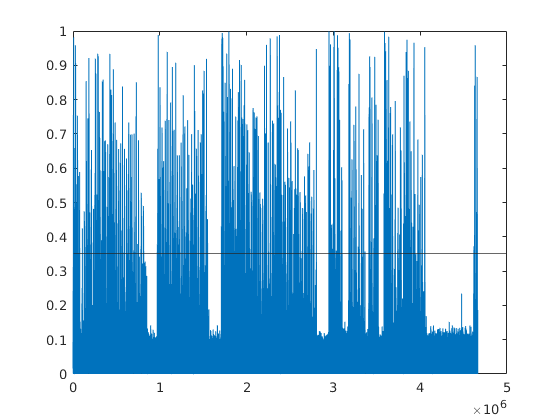

thr = 0.3500

times_sound_2 =       107740
      129455
      147729
      171466
      205501
      236825
      251322
      328678
      389884
      499687


times_sound_2 = event_detection(aluminum_sound_849(9327165/2+1:end),30000*0.4)

times_sound = [times_sound_1;times_sound_2]

times_sound =        49948
       77829
      215233
      281079
      321629
      391036
      502946
      522621
      567782
      617638


times_sound_full = double(aluminum_vector_849(times_sound))

times_sound_full =     14341175    14369056    14506460    14572306    14612856    14682263    14794173    14813848    14859009    14908865    14956454    14996923    15027901    15125479    15144911    15211591    15255785    15344462    15366903    15387718    15412337    15432593    15452994    15478647    15499623    15527378    15639800    15730398    15772993    15829091    19956301    19993553    20077650    20129504    20296347    20326119    20352930    20369657    20388740    20481286    20519553    20653466    20768967    20803206    20821116    20979038    21108419    21131904    21192216    21319917


rasters_aluminum_849 = {}


rasters_aluminum_849 =

  0×0 empty cell array



psth_aluminum_849 = []


psth_aluminum_849 =

     []



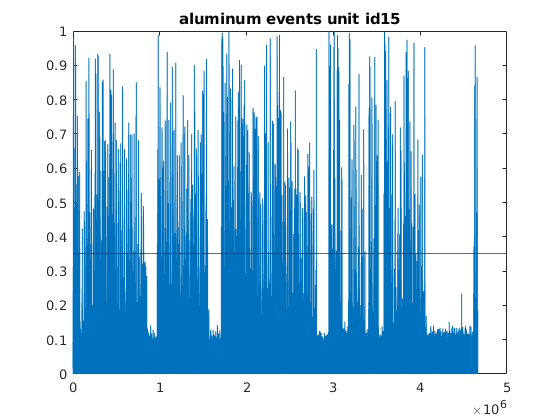

for un = 1:length(FVB103_849.experiment.Units.good.id)
    rasters_aluminum_849{un} = createRaster(times_sound_full,FVB103_849.experiment.Units.good.times(un,:),timeWind);
    title(['aluminum events unit id',num2str(un)])
    psth_aluminum_849(un,:) = psth(rasters_aluminum_849{un},numBins);
end

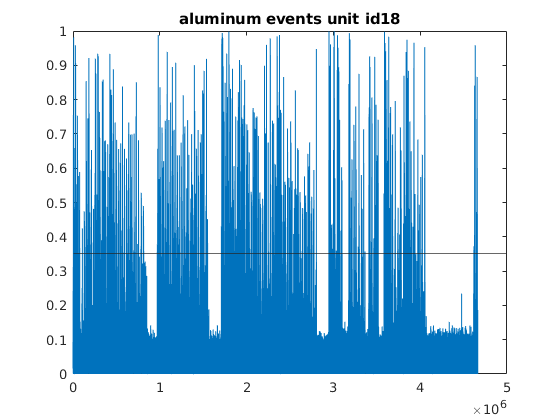


for un_1 = 1:length(FVB103_849.experiment.Units.mua.id)
    rasters_aluminum_849{un + un_1} = createRaster(times_sound_full,FVB103_849.experiment.Units.mua.times(un_1,:),timeWind);
    title(['aluminum events unit id',num2str(un_1+un)])
    psth_aluminum_849(un_1+un,:) = psth(rasters_aluminum_849{un_1+un},numBins);
end

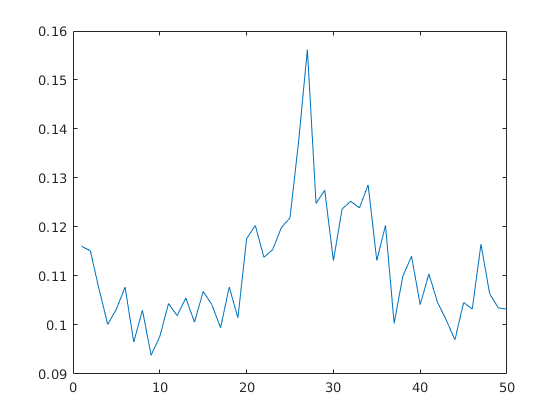

figure; plot(mean(psth_aluminum_849(FVB103_849.experiment.evokedEvents.pVal(:,2)==1,:)))

%ylim([0.06 0.15])

aluminumReal_849 = meanMatrix(times_sound_full,1,30000)

aluminumReal_849 =     14326176    14326177    14326178    14326179    14326180    14326181    14326182    14326183    14326184    14326185    14326186    14326187    14326188    14326189    14326190    14326191    14326192    14326193    14326194    14326195    14326196    14326197    14326198    14326199    14326200    14326201    14326202    14326203    14326204    14326205    14326206    14326207    14326208    14326209    14326210    14326211    14326212    14326213    14326214    14326215    14326216    14326217    14326218    14326219    14326220    14326221    14326222    14326223    14326224    14326225
    14354057    14354058    14354059    14354060    14354061    14354062    14354063    14354064    14354065    14354066    14354067    14354068    14354069    14354070    14354071    14354072    14354073    14354074    14354075    14354076    14354077    14354078    14354079    14354080    14354081    14354082    14354083    14354084    14354085    14354086    14354087    1435

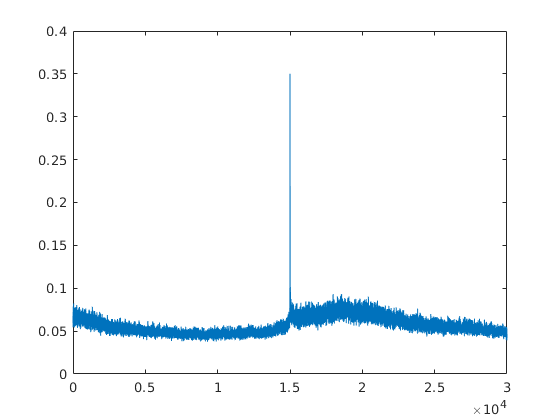

figure; plot((mean(FVB103_849.experiment.sound_events.fullSound(aluminumReal_849))+mean(FVB103_849.experiment.sound_events.fullSound(aluminumReal_849))/2))

both_psth = [psth_aluminum_757(FVB103_757.experiment.evokedEvents.pVal(:,2)==1,:);psth_aluminum_849(FVB103_849.experiment.evokedEvents.pVal(:,2)==1,:)]

both_psth =     0.0123    0.0617    0.0617    0.0741    0.0494    0.0988    0.0617    0.0741    0.0123    0.0247    0.0741    0.0370    0.0370    0.0617    0.0494    0.0370    0.0741    0.0123    0.0741         0    0.0370    0.0741    0.0370         0    0.0123    0.0123    0.1235    0.0864    0.0741    0.0494    0.0247    0.0370    0.0988    0.0494    0.0370    0.1235    0.0988    0.0617    0.0494    0.0988    0.0617    0.0741    0.0617    0.0741    0.0247    0.0494    0.0617    0.0988    0.0494    0.0741
    0.0864    0.0617    0.1111    0.0617    0.0370    0.0741    0.1605    0.0617    0.0617    0.0988    0.0741    0.0617    0.0741    0.0988    0.1481    0.1605    0.1111    0.0617    0.1235    0.0988    0.1111    0.1481    0.0988    0.0988    0.1235    0.0741    0.1358    0.0617    0.0494    0.1235    0.0741    0.0864    0.0617    0.0617    0.1358    0.0741    0.1235    0.0864    0.0617    0.1111    0.0741    0.1235    0.1235    0.1358    0.1481    0.1235    0.1111    0.0988    0.0

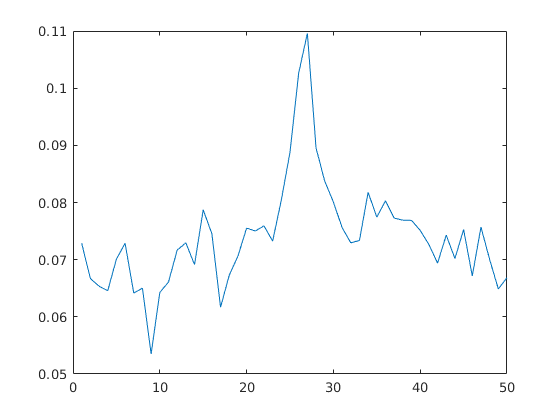

figure;
plot(mean(both_psth))

FVB849 motion

[b,a] = butter(3,5/200,"high")

b =     0.9244   -2.7733    2.7733   -0.9244


a =     1.0000   -2.8430    2.6980   -0.8546


motion_filt = filtfilt(b,a,normalize(double(motion_1),'range',[-1,1]))

motion_filt =    -0.0009    0.0304    0.0077   -0.0192   -0.0087   -0.0061    0.0058    0.0184    0.0634    0.0688    0.0793    0.0758    0.0545    0.0490    0.0126    0.0455    0.0482    0.0375    0.0559    0.0615    0.0449    0.0070   -0.0250   -0.0281   -0.0260    0.0210    0.0136    0.0088   -0.0029   -0.0150   -0.0390   -0.0219   -0.0050   -0.0167   -0.0085    0.0051   -0.0203   -0.0073   -0.0247    0.0076   -0.0120    0.0105    0.0026    0.0117   -0.0035   -0.0090   -0.0007   -0.0077   -0.0056   -0.0010


motion_filt = motion_filt(FVB103_849.experiment.Cams.whsiking.csv_start_frame+1:end)

motion_filt =    -0.0129    0.0012    0.1375    0.0146    0.0303    0.0017   -0.0405   -0.0432   -0.0109    0.0456    0.0157   -0.0085   -0.0078   -0.0151    0.0129    0.0037   -0.0329   -0.0006   -0.0139   -0.0148    0.0035   -0.0068    0.0015    0.0078    0.0043    0.0096    0.0058   -0.0158   -0.0022   -0.0153    0.0322    0.0129    0.0277   -0.0092   -0.0238    0.0004   -0.0150    0.0036    0.0045    0.0037   -0.0138   -0.0027   -0.0275   -0.0048   -0.0067    0.0105   -0.0038    0.0100    0.0130    0.0186


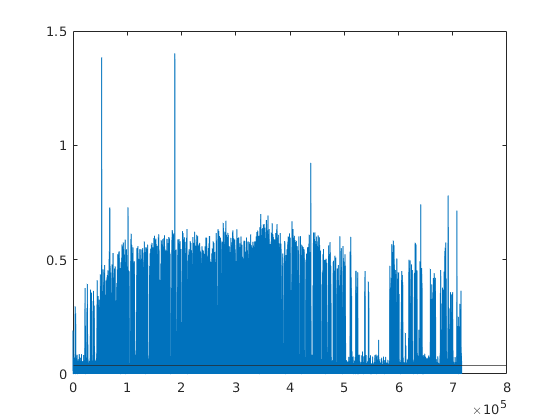

thr = 0.1500

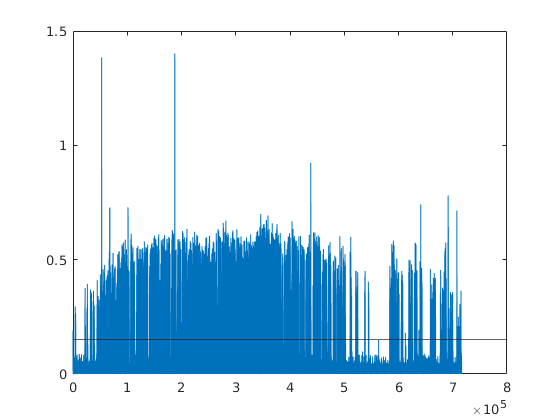

thr = 0.1500

whisk_times =         4070
        4434
        4925
       21794
       22039
       22312
       22539
       23067
       25592
       25878


whisk_times = event_detection(motion_filt,0.4*400)

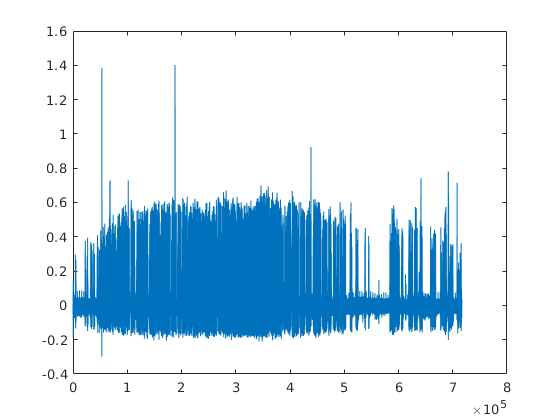

figure; plot(motion_filt)

whisk_times_op = FVB103_849.experiment.predictedSound.sampleVector(whisk_times)

whisk_times_op =       379697
      407019
      443857
     1709817
     1728202
     1748690
     1765720
     1805343
     1994836
     2016298


aluminumTimes = FVB103_849.experiment.sound_events.aluminum

aluminumTimes = 11×2 int64 matrix
   14216228   15934759
   19866859   21585390
   25517440   27235965
   29278488   30997011
   33039531   34758095
   36800614   38525130
   42451168   44163686
   44328686   46041205
   46206205   47918724
   48083724   49796286


aluminumEvents = []


aluminumEvents =

     []



%FVB103_849.experimentpredictedSound.events.aluminum = [];
for al = 1:length(aluminumTimes)
    tempEvents = whisk_times_op(find(whisk_times_op > aluminumTimes(al,1) & whisk_times_op < aluminumTimes(al,2)))
    %tempPredict = times_prediction(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))'
    aluminumEvents = [aluminumEvents;tempEvents]
    %FVB103_849.experimentpredictedSound.events.aluminum = [FVB103_849.experimentpredictedSound.events.aluminum;tempPredict]
end

tempEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


tempEvents =     20085863
    20102752
    20423120
    20437373
    20679849
    20693434
    20794673
    21046900
    21060931
    21269333


aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


tempEvents = 26736787

aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


tempEvents =     29319125
    29517246
    29532182
    29547641
    29560549
    29577808
    29625089
    29657581
    29701108
    29714174


aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


tempEvents =     33295426
    33310959
    33394184
    33411074
    33597635
    33613692
    33822173
    33920255
    33935339
    33974066


aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


tempEvents =     36809985
    36965924
    36980792
    37040971
    37078269
    37196840
    37256580
    37269788
    37288700
    37398724


aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


tempEvents =     43901518
    43918031
    43933866
    43947518
    43969808
    43986694
    44013109
    44028041
    44115325
    44130556


aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


tempEvents =     44347735
    44442449
    44529650
    44551043
    44567479
    44602671
    44641846
    44655883
    44682816
    44696485


aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


tempEvents =     46503589
    46521446
    46536833
    46594923
    46607829
    46636947
    46651120
    46676346
    46691582
    46708090


aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


tempEvents =     48096970
    48125185
    48140796
    48183943
    48199033
    48212911
    48235499
    48252532
    48327733
    48343416


aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


tempEvents =     49964558
    49991564
    50008453
    50046132
    50065039
    50080721
    50117496
    50134610
    50194046
    50208452


aluminumEvents =     14232650
    14250440
    14264167
    14278730
    14327207
    14351070
    14527359
    14543116
    14557448
    14650061


% non times
nonTimes = FVB103_849.experiment.sound_events.muted

nonTimes = 9×2 int64 matrix
    6682119    8406643
   10455171   12173700
   12338700   14051228
   16099759   17824286
   21750390   23474914
   27400965   29113488
   31162011   32874531
   34923095   36635614
   40573649   42286168


%FVB103_849.experimentpredictedSound.events.non = [];
nonEvents = []


nonEvents =

     []



for non = 1:length(nonTimes)
    tempInd = whisk_times_op(find(whisk_times_op > nonTimes(non,1) & whisk_times_op < nonTimes(non,2)))
    %tempPredict = times_prediction(find(times > nonTimes(non,1) & times < nonTimes(non,2)))'
    nonEvents = [nonEvents;tempInd]
    %FVB103_849.experimentpredictedSound.events.non = [FVB103_849.experimentpredictedSound.events.non;tempPredict];
end

tempInd =      6698489
     6738338
     6753419
     6770235
     6789518
     6816835
     7028088
     7122725
     7164671
     7216304


nonEvents =      6698489
     6738338
     6753419
     6770235
     6789518
     6816835
     7028088
     7122725
     7164671
     7216304


tempInd =     10641257
    10655219
    10668124
    10681253
    10695739
    10731462
    10846512
    10879305
    10892216
    10905277


nonEvents =      6698489
     6738338
     6753419
     6770235
     6789518
     6816835
     7028088
     7122725
     7164671
     7216304


tempInd =     12363711
    12377074
    12603864
    12617968
    12869598
    13179392
    13193720
    13410306
    13692249
    13707933


nonEvents =      6698489
     6738338
     6753419
     6770235
     6789518
     6816835
     7028088
     7122725
     7164671
     7216304


tempInd =     16455656
    16601619
    16617905
    16633364
    16742485
    16866909
    16881320
    17057898
    17071184
    17084839


nonEvents =      6698489
     6738338
     6753419
     6770235
     6789518
     6816835
     7028088
     7122725
     7164671
     7216304


tempInd =     21843433
    22521177
    22593283
    22623538
    22636815
    22714637
    22927544
    22940150
    23156060
    23381646


nonEvents =      6698489
     6738338
     6753419
     6770235
     6789518
     6816835
     7028088
     7122725
     7164671
     7216304


tempInd =     27464134
    28036888
    28368219
    28542549
    28598988
    28648217
    28673431
    28811590
    28830353
    28876802


nonEvents =      6698489
     6738338
     6753419
     6770235
     6789518
     6816835
     7028088
     7122725
     7164671
     7216304


tempInd =     31260043
    31276480
    31516843
    31533128
    31546329
    31611398
    31641343
    32285232
    32298827
    32315031


nonEvents =      6698489
     6738338
     6753419
     6770235
     6789518
     6816835
     7028088
     7122725
     7164671
     7216304


tempInd =     34923393
    34942605
    34957992
    34974874
    34990188
    35041520
    35054498
    35099304
    35129331
    35172402


nonEvents =      6698489
     6738338
     6753419
     6770235
     6789518
     6816835
     7028088
     7122725
     7164671
     7216304


tempInd =     40952962
    40968196
    41008122


nonEvents =      6698489
     6738338
     6753419
     6770235
     6789518
     6816835
     7028088
     7122725
     7164671
     7216304


% muted times
mutedTimes = FVB103_849.experiment.sound_events.non

mutedTimes = 7×2 int64 matrix
    4798592    6517119
    8571643   10290171
   17989286   19701859
   23639914   25352440
   38690130   40408649
   51850804   53575322
   53740322   53761631


%FVB103_849.experimentpredictedSound.events.muted = [];
mutedEvents = []


mutedEvents =

     []



for mut = 1:length(mutedTimes)
    tempInd = whisk_times_op(find(whisk_times_op > mutedTimes(mut,1) & whisk_times_op < mutedTimes(mut,2)))
    %tempPredict = times_prediction(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))'
    mutedEvents = [mutedEvents;tempInd]
    %FVB103_849.experimentpredictedSound.events.muted = [FVB103_849.experimentpredictedSound.events.muted;tempPredict];
end

tempInd =      4808989
     4826253
     4839679
     4860024
     4873683
     4889590
     4929072
     4946475
     4962760
     4985951


mutedEvents =      4808989
     4826253
     4839679
     4860024
     4873683
     4889590
     4929072
     4946475
     4962760
     4985951


tempInd =      8598278
     8614115
     8858534
     8877673
     8892684
     8988663
     9013059
     9108666
     9125552
     9141534


mutedEvents =      4808989
     4826253
     4839679
     4860024
     4873683
     4889590
     4929072
     4946475
     4962760
     4985951


tempInd =     18083030
    18106896
    18175414
    18289704
    18399797
    18412781
    18716189
    18769182
    19055627
    19191762


mutedEvents =      4808989
     4826253
     4839679
     4860024
     4873683
     4889590
     4929072
     4946475
     4962760
     4985951


tempInd =     23646332
    23933603
    23985084
    24340656
    24379227


mutedEvents =      4808989
     4826253
     4839679
     4860024
     4873683
     4889590
     4929072
     4946475
     4962760
     4985951


tempInd =     39199743
    39212584
    39229842
    39257454
    39270057
    39327925
    39342111
    39364924
    39394339
    39415801


mutedEvents =      4808989
     4826253
     4839679
     4860024
     4873683
     4889590
     4929072
     4946475
     4962760
     4985951


tempInd =     51968802
    52006098
    52053981
    52149435
    52186733
    52244146
    52311537
    52331422
    52359420
    52386432


mutedEvents =      4808989
     4826253
     4839679
     4860024
     4873683
     4889590
     4929072
     4946475
     4962760
     4985951


tempInd = 53760307

mutedEvents =      4808989
     4826253
     4839679
     4860024
     4873683
     4889590
     4929072
     4946475
     4962760
     4985951


rasters_aluminum_whisk_849 = {}


rasters_aluminum_whisk_849 =

  0×0 empty cell array



psth_aluminum_whisk_849 = []


psth_aluminum_whisk_849 =

     []



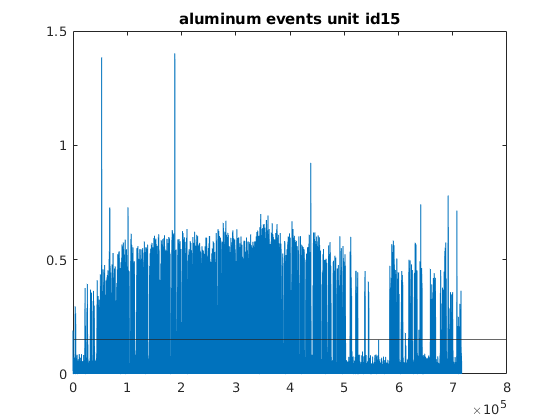

for un = 1:length(FVB103_849.experiment.Units.good.id)
    rasters_aluminum_whisk_849{un} = createRaster(aluminumEvents,FVB103_849.experiment.Units.good.times(un,:),timeWind);
    title(['aluminum events unit id',num2str(un)])
    psth_aluminum_whisk_849(un,:) = psth(rasters_aluminum_whisk_849{un},numBins);
end

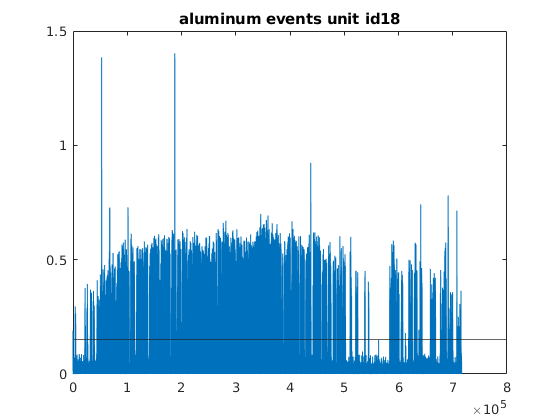


for un_1 = 1:length(FVB103_849.experiment.Units.mua.id)
    rasters_aluminum_whisk_849{un + un_1} = createRaster(aluminumEvents,FVB103_849.experiment.Units.mua.times(un_1,:),timeWind);
    title(['aluminum events unit id',num2str(un_1+un)])
    psth_aluminum_whisk_849(un_1+un,:) = psth(rasters_aluminum_whisk_849{un_1+un},numBins);
end

rasters_muted_whisk_849 = {}


rasters_muted_whisk_849 =

  0×0 empty cell array



psth_muted_whisk_849 = []


psth_muted_whisk_849 =

     []



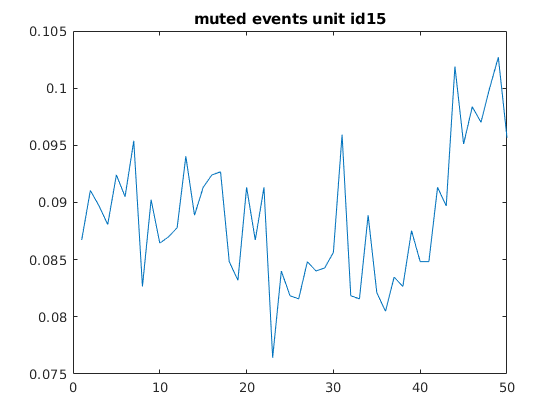

for un = 1:length(FVB103_849.experiment.Units.good.id)
    rasters_muted_whisk_849{un} = createRaster(mutedEvents,FVB103_849.experiment.Units.good.times(un,:),timeWind);
    title(['muted events unit id',num2str(un)])
    psth_muted_whisk_849(un,:) = psth(rasters_muted_whisk_849{un},numBins);
end

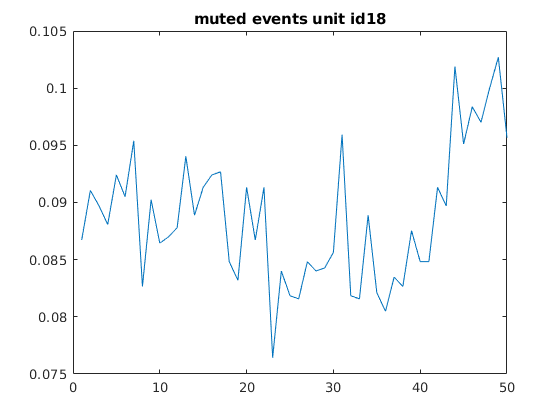


for un_1 = 1:length(FVB103_849.experiment.Units.mua.id)
    rasters_muted_whisk_849{un + un_1} = createRaster(mutedEvents,FVB103_849.experiment.Units.mua.times(un_1,:),timeWind);
    title(['muted events unit id',num2str(un_1+un)])
    psth_muted_whisk_849(un_1+un,:) = psth(rasters_muted_whisk_849{un_1+un},numBins);
end

rasters_non_whisk_849 = {}


rasters_non_whisk_849 =

  0×0 empty cell array



psth_non_whisk_849 = []


psth_non_whisk_849 =

     []



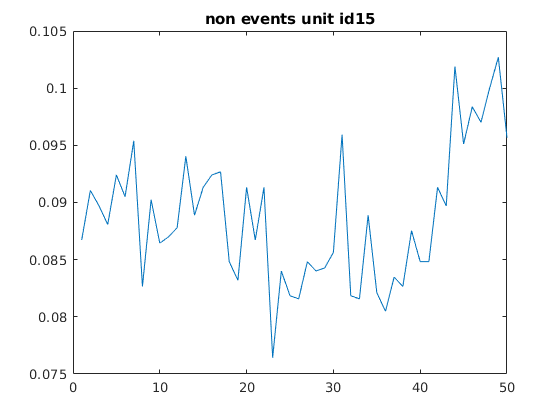

for un = 1:length(FVB103_849.experiment.Units.good.id)
    rasters_non_whisk_849{un} = createRaster(nonEvents,FVB103_849.experiment.Units.good.times(un,:),timeWind);
    title(['non events unit id',num2str(un)])
    psth_non_whisk_849(un,:) = psth(rasters_non_whisk_849{un},numBins);
end

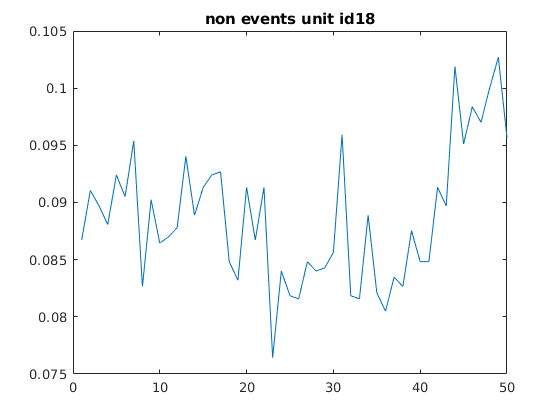


for un_1 = 1:length(FVB103_849.experiment.Units.mua.id)
    rasters_non_whisk_849{un + un_1} = createRaster(nonEvents,FVB103_849.experiment.Units.mua.times(un_1,:),timeWind);
    title(['non events unit id',num2str(un_1+un)])
    psth_non_whisk_849(un_1+un,:) = psth(rasters_non_whisk_849{un_1+un},numBins);
end

FVB757 motion

[b,a] = butter(3,5/200,"high")

motion_filt = motion_1(FVB103_757.experiment.Cams.whsiking.csv_start_frame+1:end)

motion_filt = 1×845581 single row vector
      131355      128383      575526      191885      128689      122344      109107      104146      102728      113692      117241      116135      124691      137539      131881      131748      126657      126425      126436      123850      115058      129884      146641      132663      124082      121661      120604      115252      114606      113381      114156      115317      117526      118838      120364      116014      114449      113188      116511      122591      117631      113405      112647      114992      116348      120378      114668      119744      115025      114535


motion_filt(1:120) = []

motion_filt = 1×845461 single row vector
      116056      114698      123745      111268      117475      115056      118979      119667      122060      127095      117107      123393      127843      127309      128367      132472      128202      124520      127534      120608      119145      118440      119112      115586      118526      119536      118234      113676      118727      118092      116400      114845      116369      109221      114018      123783      126506      120037      117611      113437      116401      121696      115890      112260      121494      117305      111261      113603      111694      113614


sampleVector = FVB103_757.experiment.predictedSound.sampleVector(121:end)

sampleVector =        85880
       85948
       86021
       86097
       86185
       86250
       86321
       86405
       86472
       86556


motion_filt = filtfilt(b,a,normalize(double(motion_filt),'range',[-1,1]))

motion_filt =     0.0012   -0.0008    0.0090   -0.0055    0.0012   -0.0019    0.0021    0.0026    0.0050    0.0103   -0.0012    0.0056    0.0104    0.0096    0.0106    0.0150    0.0100    0.0057    0.0090    0.0011   -0.0006   -0.0015   -0.0008   -0.0048   -0.0015   -0.0004   -0.0018   -0.0070   -0.0012   -0.0019   -0.0038   -0.0055   -0.0037   -0.0117   -0.0062    0.0049    0.0081    0.0008   -0.0018   -0.0065   -0.0030    0.0030   -0.0035   -0.0075    0.0030   -0.0016   -0.0084   -0.0057   -0.0078   -0.0055


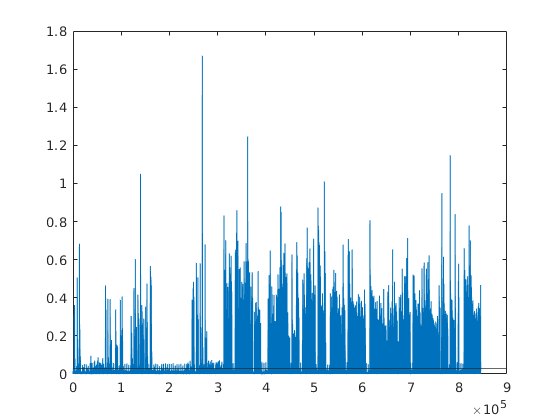

thr = 0.1500

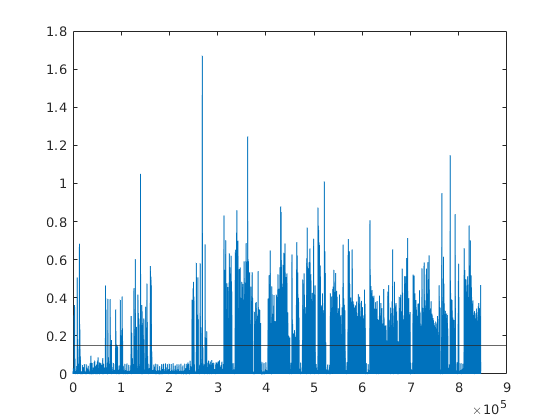

thr = 0.1500

whisk_times =         2329
        3227
        8823
        9576
       12983
       14290
       67319
       68222
       72275
       76951


whisk_times = event_detection(motion_filt,0.4*400)

figure; plot(motion_filt)

whisk_times_op = sampleVector(whisk_times)

whisk_times_op =       260583
      327972
      747925
      804431
     1060118
     1158202
     5138124
     5205889
     5510051
     5860962


aluminumTimes = FVB103_757.experiment.sound_events.aluminum

aluminumTimes = 8×2 int64 matrix
    4786818    6511339
   14216438   15928965
   16093965   17818491
   19861063   21573592
   21738592   23463119
   25505648   27224177
   59676650   61389170
   61554170   63278688


aluminumEvents = []


aluminumEvents =

     []



%FVB103_757.experimentpredictedSound.events.aluminum = [];
for al = 1:length(aluminumTimes)
    tempEvents = whisk_times_op(find(whisk_times_op > aluminumTimes(al,1) & whisk_times_op < aluminumTimes(al,2)))
    %tempPredict = times_prediction(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))'
    aluminumEvents = [aluminumEvents;tempEvents]
    %FVB103_757.experimentpredictedSound.events.aluminum = [FVB103_757.experimentpredictedSound.events.aluminum;tempPredict]
end

tempEvents =      5138124
     5205889
     5510051
     5860962
     5910131
     6027498
     6075680


aluminumEvents =      5138124
     5205889
     5510051
     5860962
     5910131
     6027498
     6075680



tempEvents =

  0×1 empty double column vector



aluminumEvents =      5138124
     5205889
     5510051
     5860962
     5910131
     6027498
     6075680



tempEvents =

  0×1 empty double column vector



aluminumEvents =      5138124
     5205889
     5510051
     5860962
     5910131
     6027498
     6075680


tempEvents =     19882712
    19924514
    19967520
    19980721
    20203831
    20632271
    20707998
    20753780
    20897413


aluminumEvents =      5138124
     5205889
     5510051
     5860962
     5910131
     6027498
     6075680
    19882712
    19924514
    19967520



tempEvents =

  0×1 empty double column vector



aluminumEvents =      5138124
     5205889
     5510051
     5860962
     5910131
     6027498
     6075680
    19882712
    19924514
    19967520


tempEvents =     25505901
    25690514
    25726611
    25917830
    26024097
    26064694
    26151524
    26327957
    26368633
    26401351


aluminumEvents =      5138124
     5205889
     5510051
     5860962
     5910131
     6027498
     6075680
    19882712
    19924514
    19967520


tempEvents =     60037808
    60948786


aluminumEvents =      5138124
     5205889
     5510051
     5860962
     5910131
     6027498
     6075680
    19882712
    19924514
    19967520


tempEvents =     61589527
    61732487
    61903145
    62101637
    62592811
    62616674
    62994455


aluminumEvents =      5138124
     5205889
     5510051
     5860962
     5910131
     6027498
     6075680
    19882712
    19924514
    19967520


% non times
nonTimes = FVB103_757.experiment.sound_events.muted

nonTimes = 10×2 int64 matrix
   12338912   14051438
   27389177   29107704
   29272704   30997226
   33045750   34764315
   34929315   36653834
   40591870   42310389
   42475389   44199905
   46248425   47972941
   50021504   51746020
   59463094   59511650


%FVB103_757.experimentpredictedSound.events.non = [];
nonEvents = []


nonEvents =

     []



for non = 1:length(nonTimes)
    tempInd = whisk_times_op(find(whisk_times_op > nonTimes(non,1) & whisk_times_op < nonTimes(non,2)))
    %tempPredict = times_prediction(find(times > nonTimes(non,1) & times < nonTimes(non,2)))'
    nonEvents = [nonEvents;tempInd]
    %FVB103_757.experimentpredictedSound.events.non = [FVB103_757.experimentpredictedSound.events.non;tempPredict];
end


tempInd =

  0×1 empty double column vector




nonEvents =

  0×1 empty double column vector



tempInd =     27451849
    27491479
    27511434
    27551512
    27592481
    27627457
    27692824
    27717510
    27777328
    27880205


nonEvents =     27451849
    27491479
    27511434
    27551512
    27592481
    27627457
    27692824
    27717510
    27777328
    27880205


tempInd =     29278023
    30434180
    30486786
    30639951
    30654434
    30718000
    30750867
    30780508
    30828087
    30854430


nonEvents =     27451849
    27491479
    27511434
    27551512
    27592481
    27627457
    27692824
    27717510
    27777328
    27880205


tempInd =     33061086
    33224392
    33501977
    33526070
    33626712
    33664300
    33792936
    33813348
    34154658
    34206208


nonEvents =     27451849
    27491479
    27511434
    27551512
    27592481
    27627457
    27692824
    27717510
    27777328
    27880205


tempInd =     35256115
    35798995


nonEvents =     27451849
    27491479
    27511434
    27551512
    27592481
    27627457
    27692824
    27717510
    27777328
    27880205


tempInd =     40685159
    40880430
    41053336
    41103316
    41172509
    41277498
    41326806
    41487926
    41517492
    41566133


nonEvents =     27451849
    27491479
    27511434
    27551512
    27592481
    27627457
    27692824
    27717510
    27777328
    27880205


tempInd =     42877937
    43068700
    43210464
    43446030
    43831249
    43851660
    43874249
    43974360
    44163621
    44196797


nonEvents =     27451849
    27491479
    27511434
    27551512
    27592481
    27627457
    27692824
    27717510
    27777328
    27880205


tempInd =     46293272
    46768996
    47519075
    47550442
    47579563
    47681625
    47735510


nonEvents =     27451849
    27491479
    27511434
    27551512
    27592481
    27627457
    27692824
    27717510
    27777328
    27880205


tempInd =     50025836
    50055857
    50221558
    50392592
    50489024
    50527607
    50539904
    50630410
    50787033
    50829054


nonEvents =     27451849
    27491479
    27511434
    27551512
    27592481
    27627457
    27692824
    27717510
    27777328
    27880205



tempInd =

  0×1 empty double column vector



nonEvents =     27451849
    27491479
    27511434
    27551512
    27592481
    27627457
    27692824
    27717510
    27777328
    27880205


% muted times
mutedTimes = FVB103_757.experiment.sound_events.non

mutedTimes = 15×2 int64 matrix
    6676339    8400861
    8565861   10290384
   10455384   12173912
   17983491   19696063
   23628119   25340648
   31162226   32880750
   36818834   38543350
   38708350   40426870
   44364905   46083425
   48137941   49856504


%FVB103_757.experimentpredictedSound.events.muted = [];
mutedEvents = []


mutedEvents =

     []



for mut = 1:length(mutedTimes)
    tempInd = whisk_times_op(find(whisk_times_op > mutedTimes(mut,1) & whisk_times_op < mutedTimes(mut,2)))
    %tempPredict = times_prediction(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))'
    mutedEvents = [mutedEvents;tempInd]
    %FVB103_757.experimentpredictedSound.events.muted = [FVB103_757.experimentpredictedSound.events.muted;tempPredict];
end

tempInd =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =      9132593
     9166815
     9191884
     9220022
     9570784
     9636980
     9656114
     9787894
     9841180
     9854761


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     10593740
    10626459
    10659852
    10705105
    10780003
    10834858
    10892120
    10913358
    11087470
    11135874


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     18610907
    18682648
    18778857
    18825386
    18893754
    19280993
    19328794
    19351607
    19379077
    19505156


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     23696994
    23756582
    23797339
    23843035
    23920632
    23945471
    23983970
    24027800
    24114329
    24136090


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     31181034
    31195139
    31217432
    31507862
    31582076
    31614200
    31677086
    31699074
    31734420
    31789279


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     37761065
    38214274
    38270335


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     39018012
    39152194
    39175158
    39195269
    39349187
    39417933
    40134244
    40250415
    40268201
    40294992


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     44377434
    44646173
    45085941
    45116184
    45317075
    45382370
    45406163
    45461773


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     48143154
    48238688
    48355010
    48380000
    48440792
    48519438
    48577001
    48591035
    48659922
    48772272


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     51994828
    52150843
    52451107
    52507160
    52995862


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     53904520
    54159445
    54182948
    54233439
    54336261
    54475988
    54539551
    54562515
    54699251
    55248141


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     55979306
    56083996
    56211499
    56228537
    56271986
    56300054
    56316341
    56408644
    56428759
    56505458


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


tempInd =     57666569
    57717674
    58282920
    58416805
    58794068


mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909



tempInd =

  0×1 empty double column vector



mutedEvents =      6704784
     6753946
     6795144
     6923920
     7455322
     7520685
     7556559
     7569317
     7624402
     7640909


rasters_aluminum_whisk_757 = {}


rasters_aluminum_whisk_757 =

  0×0 empty cell array



psth_aluminum_whisk_757 = []


psth_aluminum_whisk_757 =

     []



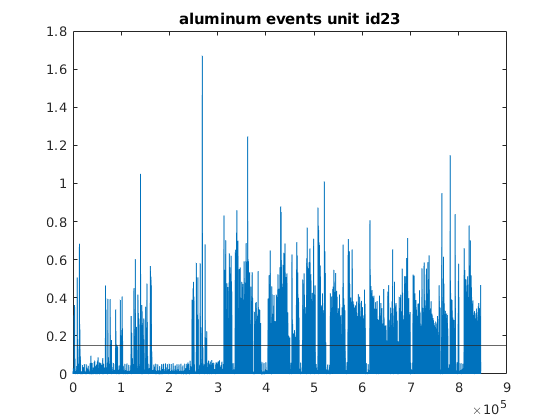

for un = 1:length(FVB103_757.experiment.Units.good.id)
    rasters_aluminum_whisk_757{un} = createRaster(aluminumEvents,FVB103_757.experiment.Units.good.times(un,:),timeWind);
    title(['aluminum events unit id',num2str(un)])
    psth_aluminum_whisk_757(un,:) = psth(rasters_aluminum_whisk_757{un},numBins);
end

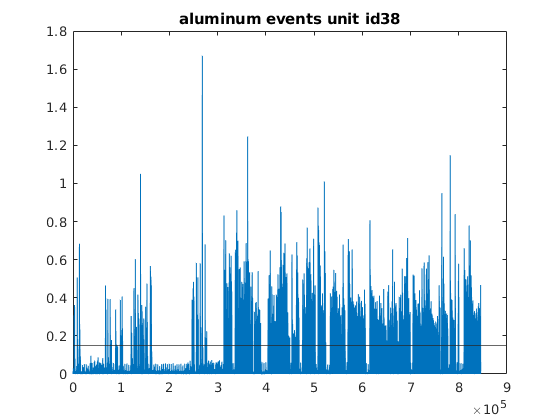


for un_1 = 1:length(FVB103_757.experiment.Units.mua.id)
    rasters_aluminum_whisk_757{un + un_1} = createRaster(aluminumEvents,FVB103_757.experiment.Units.mua.times(un_1,:),timeWind);
    title(['aluminum events unit id',num2str(un_1+un)])
    psth_aluminum_whisk_757(un_1+un,:) = psth(rasters_aluminum_whisk_757{un_1+un},numBins);
end

rasters_muted_whisk_757 = {}


rasters_muted_whisk_757 =

  0×0 empty cell array



psth_muted_whisk_757 = []


psth_muted_whisk_757 =

     []



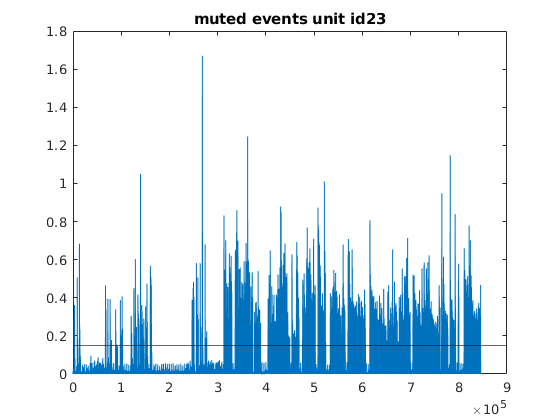

for un = 1:length(FVB103_757.experiment.Units.good.id)
    rasters_muted_whisk_757{un} = createRaster(mutedEvents,FVB103_757.experiment.Units.good.times(un,:),timeWind);
    title(['muted events unit id',num2str(un)])
    psth_muted_whisk_757(un,:) = psth(rasters_muted_whisk_757{un},numBins);
end

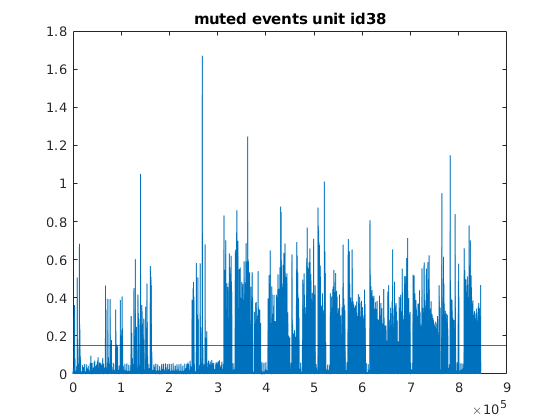


for un_1 = 1:length(FVB103_757.experiment.Units.mua.id)
    rasters_muted_whisk_757{un + un_1} = createRaster(mutedEvents,FVB103_757.experiment.Units.mua.times(un_1,:),timeWind);
    title(['muted events unit id',num2str(un_1+un)])
    psth_muted_whisk_757(un_1+un,:) = psth(rasters_muted_whisk_757{un_1+un},numBins);
end

rasters_non_whisk_757 = {}


rasters_non_whisk_757 =

  0×0 empty cell array



psth_non_whisk_757 = []


psth_non_whisk_757 =

     []



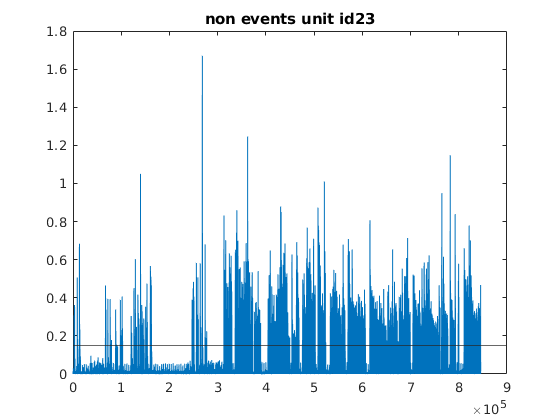

for un = 1:length(FVB103_757.experiment.Units.good.id)
    rasters_non_whisk_757{un} = createRaster(nonEvents,FVB103_757.experiment.Units.good.times(un,:),timeWind);
    title(['non events unit id',num2str(un)])
    psth_non_whisk_757(un,:) = psth(rasters_non_whisk_757{un},numBins);
end

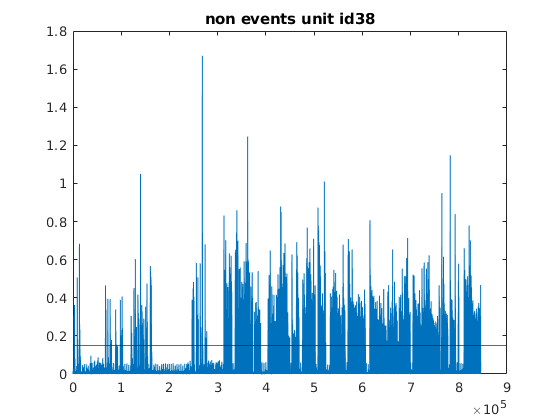


for un_1 = 1:length(FVB103_757.experiment.Units.mua.id)
    rasters_non_whisk_757{un + un_1} = createRaster(nonEvents,FVB103_757.experiment.Units.mua.times(un_1,:),timeWind);
    title(['non events unit id',num2str(un_1+un)])
    psth_non_whisk_757(un_1+un,:) = psth(rasters_non_whisk_757{un_1+un},numBins);
end

psth_muted_whisk = [psth_muted_whisk_757;psth_muted_whisk_849]

psth_muted_whisk =     0.0847    0.1073    0.0847    0.0791    0.0847    0.0734    0.0621    0.0395    0.1017    0.0508    0.0847    0.0621    0.0904    0.0791    0.0508    0.1243    0.1073    0.1073    0.0847    0.0791    0.0734    0.0565    0.0621    0.0621    0.0678    0.0960    0.0960    0.0621    0.1582    0.1130    0.0960    0.0960    0.0791    0.0678    0.0565    0.0791    0.0791    0.0339    0.0621    0.0791    0.0734    0.0621    0.1073    0.0678    0.0395    0.1130    0.0904    0.0847    0.0960    0.0452
    0.0847    0.0339    0.0791    0.0621    0.0508    0.0226    0.0508    0.0452    0.0678    0.0678    0.1186    0.0904    0.0621    0.0452    0.0452    0.0621    0.0791    0.0508    0.1017    0.0508    0.0678    0.1017    0.0678    0.0904    0.0565    0.0395    0.1412    0.0678    0.0565    0.0678    0.0791    0.0339    0.0678    0.1017    0.0960    0.0678    0.0734    0.0678    0.0734    0.0678    0.0621    0.0791    0.0621    0.0847    0.0621    0.0395    0.1017    0.0508

psth_aluminum_whisk = [psth_aluminum_whisk_757;psth_aluminum_whisk_849]

psth_aluminum_whisk =     0.0909    0.0455    0.0227    0.0455    0.0227    0.0227    0.0682    0.0682         0    0.1818         0    0.0455    0.0455    0.0909    0.0227    0.0227    0.0682    0.0909    0.0455    0.0227    0.0455    0.0227    0.1136    0.0455    0.1818    0.0455    0.0455    0.0455    0.1136         0    0.0227         0    0.0455    0.0227         0    0.1136    0.0455    0.0227    0.0682    0.0455    0.0909    0.0227    0.0227    0.0909    0.1136    0.0682    0.0909    0.0455    0.0682    0.0455
    0.0682    0.0682    0.1591    0.0909    0.0682    0.1364    0.0682    0.1364    0.1591    0.0909    0.0682    0.0682    0.0682    0.2045    0.0682    0.1364    0.0682    0.1818    0.1364    0.1591    0.1136    0.0455    0.0909    0.1818    0.1364    0.0909    0.0682    0.0682    0.1136    0.1818    0.1818    0.0909    0.1136    0.1364    0.0909    0.0682    0.1364    0.1591    0.1136    0.0682    0.1136    0.1364    0.1136    0.1818    0.0909    0.1591    0.1136    0.0

psth_non_whisk = [psth_non_whisk_757;psth_non_whisk_849]

psth_non_whisk =     0.0458    0.1069    0.1069    0.0458    0.0305    0.0458    0.0916    0.0611    0.0611    0.1145    0.0916    0.0687    0.0916    0.0763    0.0458    0.0992    0.1527    0.0611    0.0382    0.1069    0.0916    0.0611    0.0840    0.0992    0.0611    0.1069    0.0916    0.0840    0.0763    0.0916    0.0840    0.0458    0.0382    0.1221    0.0687    0.1221    0.0611    0.1221    0.0840    0.0687    0.0763    0.1298    0.0382    0.0458    0.1069    0.0840    0.0916    0.0687    0.0687    0.0382
    0.0916    0.0611    0.0534    0.0763    0.0916    0.0916    0.0763    0.0763    0.0763    0.0916    0.0992    0.0840    0.0763    0.0611    0.0611    0.1069    0.0840    0.0916    0.0611    0.0916    0.0687    0.0763    0.0611    0.0916    0.0229    0.0992    0.0534    0.0916    0.0687    0.0382    0.1069    0.0534    0.0687    0.0763    0.0763    0.1069    0.0687    0.0840    0.0916    0.0458    0.0611    0.0840    0.0382    0.0458    0.1221    0.0992    0.0458    0.0534  

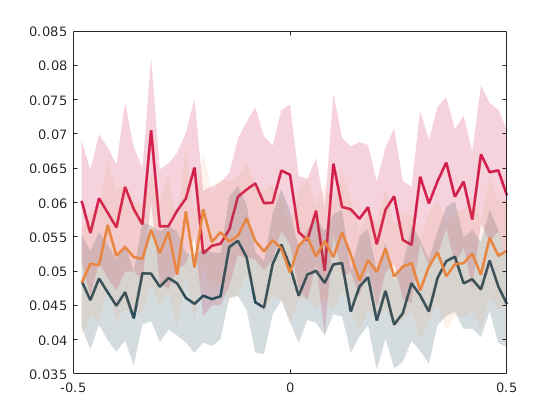

figure;
plot_areaerrorbar(psth_aluminum_whisk,optionsAl)
hold on
plot_areaerrorbar(psth_muted_whisk,optionsMu)
hold on
plot_areaerrorbar(psth_non_whisk,optionsNo)